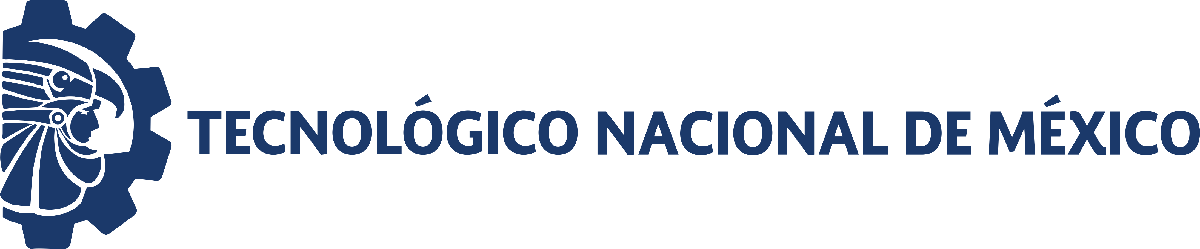                                 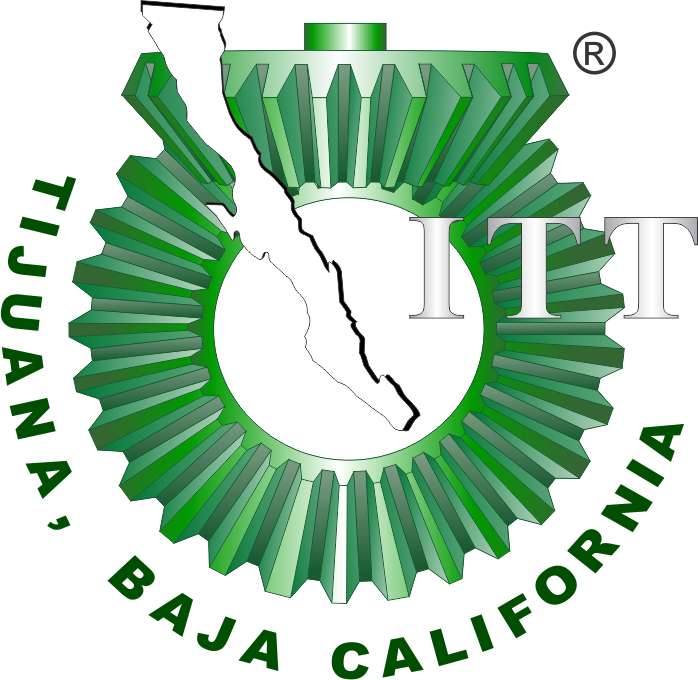

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 2: Caos en sistemas biológicos

## Información general

                                                                                                                    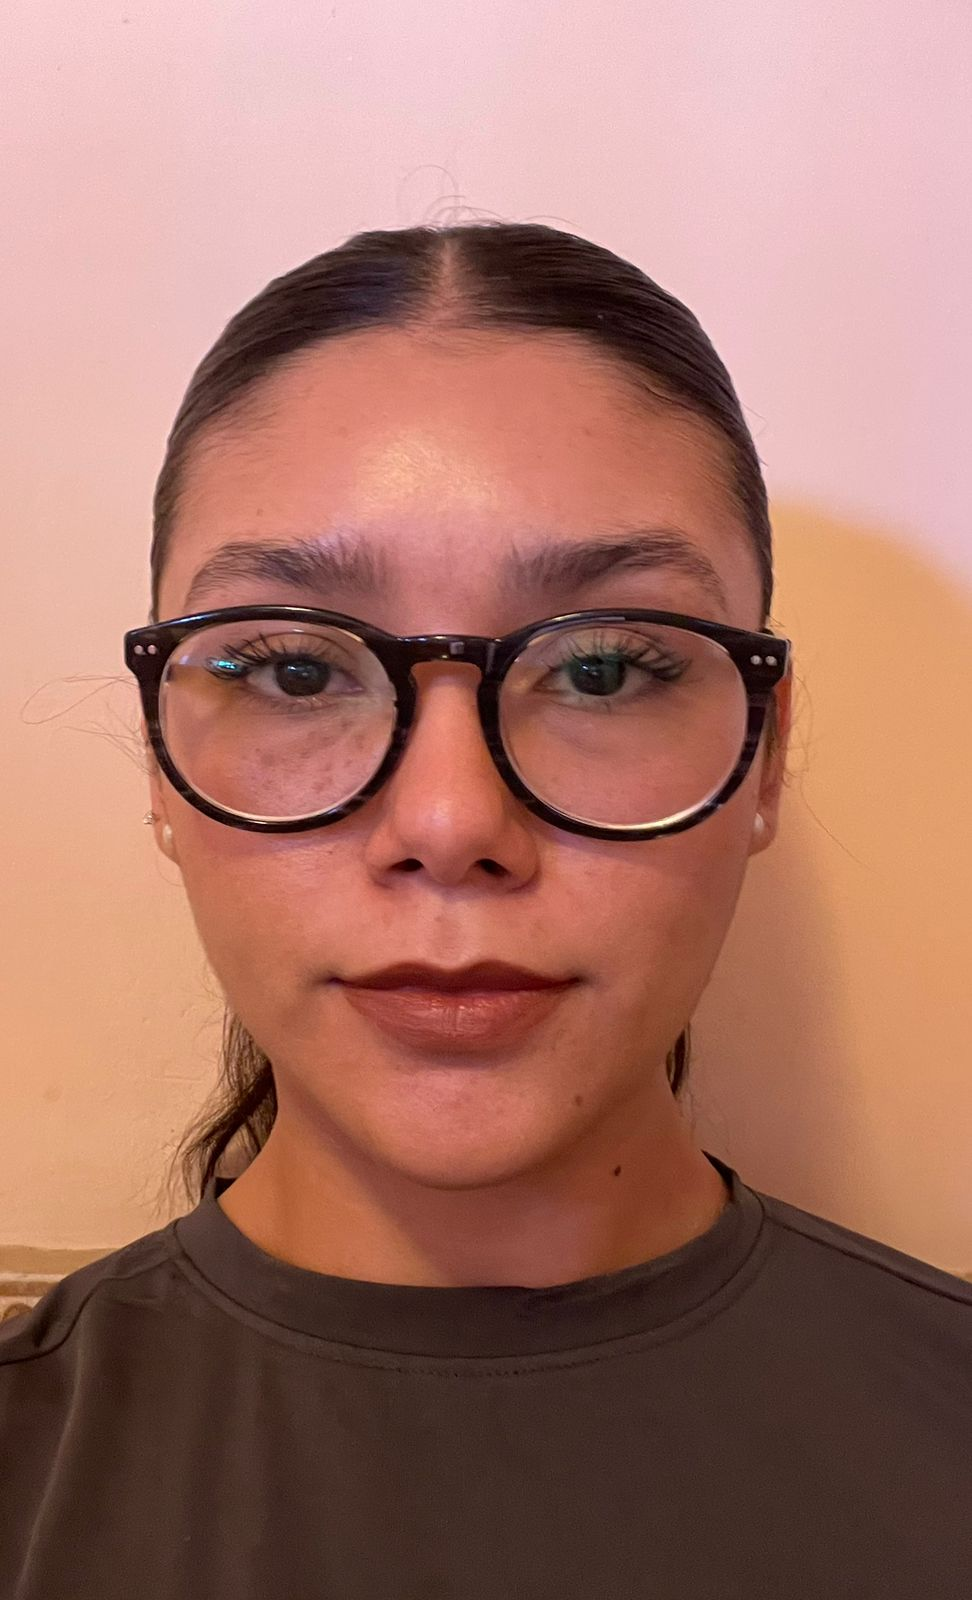

Nombre del alumno: **Maria Belen Galindo Ramirez **

Número de control: **22211755**

Correo institucional: **l22211755@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Descripción

Comparar métodos de diferencias finitas para solucionar sistemas de ODEs no lineales de primer orden que exhiben diferentes conjuntos compactos invariantes para diferentes valores en sus parámetros y/o condiciones iniciales. El modelo matemático está compuesto por las siguientes tres EDOs de primer orden:


$$\dot x = r_1 x (1-b_1x)-a_{12}xy-a_{13}xz
$$



$$\dot y = r_2y(1-b_2y)-a_{21}xy$$



$$\dot z = (r_3-a_{31})xz-d_3z+\rho_i$$


donde la variable de estado $x\left(t\right)$ representa la población de células anormales o patalógicas, la variable de estado $y\left(t\right)$ la población de células normales o sanas y la variable de estado $z\left(t\right)$ población de células efectoras (citotóxicas o NK); la descripción y valores de los parámetros se presenta a continuación:

$r_1 =1:$ Tasa de crecimiento de las células patológicas.

$b_1 =1:$ Capacidad de carga máxima de las células patológicas.

$a_{12} \in \left\lbrack 0,1\right\rbrack :$ Fracción de células patológicas eliminadas por las células sanas.

$a_{13} =2\ldotp 5:$ Fracción de células patológicas eliminadas por células efectoras.

$r_2 =0\ldotp 6:$ Tasa de crecimiento de las células sanas.

$b_2 =1:$ Capacidad de carga máxima de las células sanas.

$a_{21} =1\ldotp 5:$ Fracción de células sanas eliminadas por las células patológicas.

$r_3 =3:$ Tasa de reclutamiento máximo de células efectoras.

$a_{31} =0\ldotp 3:$ Fracción de células efectoras inactivadas por las células patológicas.

$d_3 =0\ldotp 4:$ Tasa de muerte de las células efectoras.

$\rho_i \left(t\right):$ Tratamiento de inmunoterapia.

Cabe destacar que la dinámica del sistema se localiza en octante no negativo definido por el siguiente dominio:


$$\mathbf{R}_{+,0}^{3}=\left\{ x\left( t\right) \geq 0,y\left( t\right) \geq 0,z\left( t\right) \geq 0\right\}$$


El sistema exhibe diferentes dinámicas para distintos valores del parámetro de bifurcación $a_{12}$, como se indica a continuación:

- Un atractor caótico con $a_{12} =1$, en el intervalo de tiempo $t\in \left\lbrack 0,1000\right\rbrack$ y las condiciones iniciales:$\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 555,0\ldotp 148,0\ldotp 172\right)\ldotp$

- Una órbita periódica con $a_{12} =0\ldotp 9$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 254781,0\ldotp 115167,0\ldotp 600527\right)\ldotp$

- Un ciclo límite interno con $a_{12} =0\ldotp 8$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 2,0\ldotp 6,0\ldotp 1\right)\ldotp$

- Un ciclo límite externo con $a_{12} =0\ldotp 75$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 4,0\ldotp 2,0\ldotp 4\right)\ldotp$

- Convergencia hacia un punto de equilibrio con $a_{12} =0\ldotp 5$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 5,0\ldotp 5,0\ldotp 4\right)\ldotp$

                                                        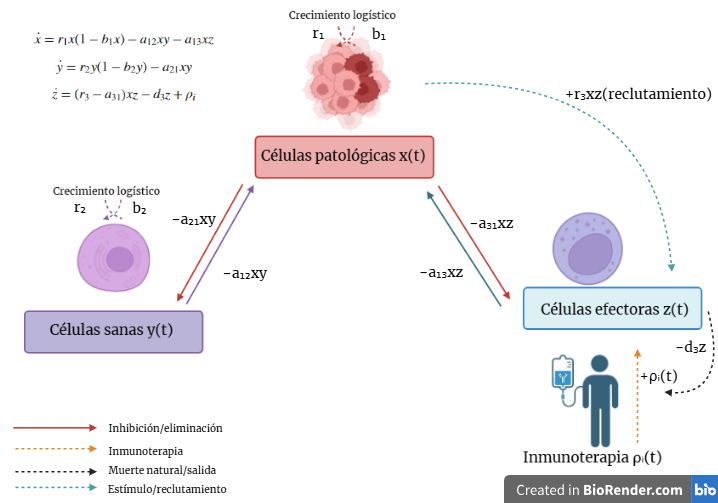

[Figura representativa del sistema elaborada en BioRender] 

Figura. Generar la figura del sistema presa-depredador con [https://bioart.niaid.nih.gov/](https://bioart.niaid.nih.gov/) o [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., *Syllabus para Biología de Sistemas y Gemelos Digitales*, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Itik, M., & Banks, S. P. (2010). Chaos in a three-dimensional cancer model. *international Journal of bifurcation and chaos*, *20*(01), 71-79. [https://doi.org/10.1142/S0218127410025417](https://doi.org/10.1142/S0218127410025417)

[3] Bryan, Kurt. *Differential equations: A toolbox for modeling the world*. Simiode, 2022. Permalink: [https://www.simiode.org/resources/8307](https://www.simiode.org/resources/8307) 

clc; clear; close all; warning('off')

## Puntos de equilibrio

syms x y z 
syms r1 b1 a12 a13 
syms r2 b2 a21 
syms r3 a31 d3 rhoi
dx_dt =  r1*x*(1 -b1*x) - a12*x*y -a13*x*z == 0;
dy_dt = r2*y*(1 -b2*y) - a21*x*y == 0;
dz_dt = (r3 - a31)*x*z - d3*z + rhoi == 0;
E = solve([dx_dt,dy_dt,dz_dt],[x,y,z]);
fprintf(['Puntos de equilibrio del sistema: ', num2str(length(E.x))]);

Puntos de equilibrio del sistema: 6

for i = 1:6
    disp([E.x(i);E.y(i);E.z(i)])
end 

$$\begin{array}{l} \left(\begin{array}{c} \frac{r_{1}-\frac{a_{13}\,\sigma_{1}}{2\,\left(a_{13}\,a_{31}-a_{13}\,r_{3}\right)}}{b_{1}\,r_{1}}\\ 0\\ \frac{\sigma_{1}}{2\,\left(a_{13}\,a_{31}-a_{13}\,r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{31}\,r_{1}-r_{1}\,r_{3}-\sqrt{r_{1}\,\left(r_{1}\,{a_{31}}^{2}+2\,r_{1}\,a_{31}\,b_{1}\,d_{3}-4\,a_{13}\,\mathrm{rhoi}\,a_{31}\,b_{1}-2\,r_{1}\,a_{31}\,r_{3}+r_{1}\,{b_{1}}^{2}\,{d_{3}}^{2}-2\,r_{1}\,b_{1}\,d_{3}\,r_{3}+4\,a_{13}\,\mathrm{rhoi}\,b_{1}\,r_{3}+r_{1}\,{r_{3}}^{2}\right)}+b_{1}\,d_{3}\,r_{1} \end{array}$$

$$\begin{array}{l} \left(\begin{array}{c} \frac{r_{2}\,\left(a_{12}-b_{2}\,r_{1}\right)}{\sigma_{2}}-\frac{\sigma_{1}}{2\,\sigma_{2}\,\left(a_{31}-r_{3}\right)}\\ \frac{a_{21}\,r_{1}-b_{1}\,r_{1}\,r_{2}}{\sigma_{2}}+\frac{a_{21}\,\sigma_{1}}{2\,b_{2}\,r_{2}\,\sigma_{2}\,\left(a_{31}-r_{3}\right)}\\ -\frac{\sigma_{1}}{2\,a_{13}\,b_{2}\,r_{2}\,\left(a_{31}-r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{a_{12}}^{2}\,{a_{21}}^{2}\,{d_{3}}^{2}+2\,{a_{12}}^{2}\,a_{21}\,a_{31}\,d_{3}\,r_{2}-2\,{a_{12}}^{2}\,a_{21}\,d_{3}\,r_{2}\,r_{3}+{a_{12}}^{2}\,{a_{31}}^{2}\,{r_{2}}^{2}-2\,{a_{12}}^{2}\,a_{31}\,{r_{2}}^{2}\,r_{3}+{a_{12}}^{2}\,{r_{2}}^{2}\,{r_{3}}^{2}-2\,a_{12}\,a_{21}\,a_{31}\,b_{2}\,d_{3}\,r_{1}\,r_{2}+4\,a_{13}\,\mathrm{rhoi}\,a_{12}\,a_{21}\,a_{31}\,b_{2}\,r_{2}-2\,a_{12}\,a_{21}\,b_{1}\,b_{2}\,{d_{3}}^{2}\,r_{1}\,r_{2}+2\,a_{12}\,a_{21}\,b_{2}\,d_{3}\,r_{1}\,r_{2}\,r_{3}-4\,a_{13}\,\mathrm{rhoi}\,a_{12}\,a_{21}\,b_{2}\,r_{2}\,r_{3}-2\,a_{12}\,{a_{31}}^{2}\,b_{2}\,r_{1}\,{r_{2}}^{2}-2\,a_{12}\,a_{31}\,b_{1}\,b_{2}\,d_{3}\,r_{1}\,{r_{2}}^{2}+4\,a_{12}\,a_{31}\,b_{2}\,r_{1}\,{r_{2}}^{2}\,r_{3}+2\,a_{12}\,b_{1}\,b_{2}\,d_{3}\,r_{1}\,{r_{2}}^{2}\,r_{3}-2\,a_{12}\,b_{2}\,r_{1}\,{r_{2}}^{2}\,{r_{3}}^{2}+{a_{31}}^{2}\,{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}+2\,a_{31}\,b_{1}\,{b_{2}}^{2}\,d_{3}\,{r_{1}}^{2}\,{r_{2}}^{2}-4\,a_{13}\,\mathrm{rhoi}\,a_{31}\,b_{1}\,{b_{2}}^{2}\,r_{1}\,{r_{2}}^{2}-2\,a_{31}\,{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}\,r_{3}+{b_{1}}^{2}\,{b_{2}}^{2}\,{d_{3}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}-2\,b_{1}\,{b_{2}}^{2}\,d_{3}\,{r_{1}}^{2}\,{r_{2}}^{2}\,r_{3}+4\,a_{13}\,\mathrm{rhoi}\,b_{1}\,{b_{2}}^{2}\,r_{1}\,{r_{2}}^{2}\,r_{3}+{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}\,{r_{3}}^{2}}+a_{12}\,a_{21}\,d_{3}+a_{12}\,a_{31}\,r_{2}-a_{12}\,r_{2}\,r_{3}-a_{31}\,b_{2}\,r_{1}\,r_{2}+b_{2}\,r_{1}\,r_{2}\,r_{3}-b_{1}\,b_{2}\,d_{3}\,r_{1}\,r_{2}\\ \sigma_{2}=a_{12}\,a_{21}-b_{1}\,b_{2}\,r_{1}\,r_{2} \end{array}$$

$$\begin{array}{l} \left(\begin{array}{c} \frac{r_{2}\,\left(a_{12}-b_{2}\,r_{1}\right)}{\sigma_{2}}+\frac{\sigma_{1}}{2\,\sigma_{2}\,\left(a_{31}-r_{3}\right)}\\ \frac{a_{21}\,r_{1}-b_{1}\,r_{1}\,r_{2}}{\sigma_{2}}-\frac{a_{21}\,\sigma_{1}}{2\,b_{2}\,r_{2}\,\sigma_{2}\,\left(a_{31}-r_{3}\right)}\\ \frac{\sigma_{1}}{2\,a_{13}\,b_{2}\,r_{2}\,\left(a_{31}-r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{a_{12}}^{2}\,{a_{21}}^{2}\,{d_{3}}^{2}+2\,{a_{12}}^{2}\,a_{21}\,a_{31}\,d_{3}\,r_{2}-2\,{a_{12}}^{2}\,a_{21}\,d_{3}\,r_{2}\,r_{3}+{a_{12}}^{2}\,{a_{31}}^{2}\,{r_{2}}^{2}-2\,{a_{12}}^{2}\,a_{31}\,{r_{2}}^{2}\,r_{3}+{a_{12}}^{2}\,{r_{2}}^{2}\,{r_{3}}^{2}-2\,a_{12}\,a_{21}\,a_{31}\,b_{2}\,d_{3}\,r_{1}\,r_{2}+4\,a_{13}\,\mathrm{rhoi}\,a_{12}\,a_{21}\,a_{31}\,b_{2}\,r_{2}-2\,a_{12}\,a_{21}\,b_{1}\,b_{2}\,{d_{3}}^{2}\,r_{1}\,r_{2}+2\,a_{12}\,a_{21}\,b_{2}\,d_{3}\,r_{1}\,r_{2}\,r_{3}-4\,a_{13}\,\mathrm{rhoi}\,a_{12}\,a_{21}\,b_{2}\,r_{2}\,r_{3}-2\,a_{12}\,{a_{31}}^{2}\,b_{2}\,r_{1}\,{r_{2}}^{2}-2\,a_{12}\,a_{31}\,b_{1}\,b_{2}\,d_{3}\,r_{1}\,{r_{2}}^{2}+4\,a_{12}\,a_{31}\,b_{2}\,r_{1}\,{r_{2}}^{2}\,r_{3}+2\,a_{12}\,b_{1}\,b_{2}\,d_{3}\,r_{1}\,{r_{2}}^{2}\,r_{3}-2\,a_{12}\,b_{2}\,r_{1}\,{r_{2}}^{2}\,{r_{3}}^{2}+{a_{31}}^{2}\,{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}+2\,a_{31}\,b_{1}\,{b_{2}}^{2}\,d_{3}\,{r_{1}}^{2}\,{r_{2}}^{2}-4\,a_{13}\,\mathrm{rhoi}\,a_{31}\,b_{1}\,{b_{2}}^{2}\,r_{1}\,{r_{2}}^{2}-2\,a_{31}\,{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}\,r_{3}+{b_{1}}^{2}\,{b_{2}}^{2}\,{d_{3}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}-2\,b_{1}\,{b_{2}}^{2}\,d_{3}\,{r_{1}}^{2}\,{r_{2}}^{2}\,r_{3}+4\,a_{13}\,\mathrm{rhoi}\,b_{1}\,{b_{2}}^{2}\,r_{1}\,{r_{2}}^{2}\,r_{3}+{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}\,{r_{3}}^{2}}-a_{12}\,a_{21}\,d_{3}-a_{12}\,a_{31}\,r_{2}+a_{12}\,r_{2}\,r_{3}+a_{31}\,b_{2}\,r_{1}\,r_{2}-b_{2}\,r_{1}\,r_{2}\,r_{3}+b_{1}\,b_{2}\,d_{3}\,r_{1}\,r_{2}\\ \sigma_{2}=a_{12}\,a_{21}-b_{1}\,b_{2}\,r_{1}\,r_{2} \end{array}$$

$$\left(\begin{array}{c} 0\\ \frac{1}{b_{2}}\\ \frac{\mathrm{rhoi}}{d_{3}} \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{c} \frac{r_{1}-\frac{a_{13}\,\sigma_{1}}{2\,\left(a_{13}\,a_{31}-a_{13}\,r_{3}\right)}}{b_{1}\,r_{1}}\\ 0\\ \frac{\sigma_{1}}{2\,\left(a_{13}\,a_{31}-a_{13}\,r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{31}\,r_{1}-r_{1}\,r_{3}+\sqrt{r_{1}\,\left(r_{1}\,{a_{31}}^{2}+2\,r_{1}\,a_{31}\,b_{1}\,d_{3}-4\,a_{13}\,\mathrm{rhoi}\,a_{31}\,b_{1}-2\,r_{1}\,a_{31}\,r_{3}+r_{1}\,{b_{1}}^{2}\,{d_{3}}^{2}-2\,r_{1}\,b_{1}\,d_{3}\,r_{3}+4\,a_{13}\,\mathrm{rhoi}\,b_{1}\,r_{3}+r_{1}\,{r_{3}}^{2}\right)}+b_{1}\,d_{3}\,r_{1} \end{array}$$

$$\left(\begin{array}{c} 0\\ 0\\ \frac{\mathrm{rhoi}}{d_{3}} \end{array}\right)$$

## Matriz Jacobiana

dx_dt = r1*x*(1-b1*x) - a12*x*y - a13*x*z;
dy_dt = r2*y*(1-b2*y) - a21*x*y;
dz_dt = (r3 - a31)*x*z - d3*z +rhoi;
J = jacobian([dx_dt,dy_dt,dz_dt],[x,y,z]);
fprintf('Matriz Jacobiana: \n'); disp(J)

Matriz Jacobiana: 


$$\left(\begin{array}{ccc} -a_{12}\,y-a_{13}\,z-r_{1}\,\left(b_{1}\,x-1\right)-b_{1}\,r_{1}\,x & -a_{12}\,x & -a_{13}\,x\\ -a_{21}\,y & -a_{21}\,x-r_{2}\,\left(b_{2}\,y-1\right)-b_{2}\,r_{2}\,y & 0\\ -z\,\left(a_{31}-r_{3}\right) & 0 & -d_{3}-x\,\left(a_{31}-r_{3}\right) \end{array}\right)$$

## Comparación de métodos numéricos: Atractor Caótico

D = getdata('chaos'); f0 = D.f0; par = D.par;
dt = 1E-3; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 8.889e-02)
eq3        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -7.4e-02+5.8e-01i -7.4e-02-5.8e-01i +3.8e-01+0.0e+00i unstable  
eq2        -6.1e-01+0.0e+00i +4.1e-02+2.3e-01i +4.1e-02-2.3e-01i unstable  
eq3        -6.0e-01+0.0e+00i +0.0e+00+0.0e+00i -4.0e-01+0.0e+00i unidentified
eq4        -6.0e-01+0.0e+00i +0.0e+00+0.0e+00i -4.0e-01+0.0e+00i unidentified
eq5        -1.0e+00+0.0e+00i -9.0e-01+0.0e+00i +2.3e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i +6.0e-01+0.0e+00i +1.0e+00+0.0e+00i

### Euler

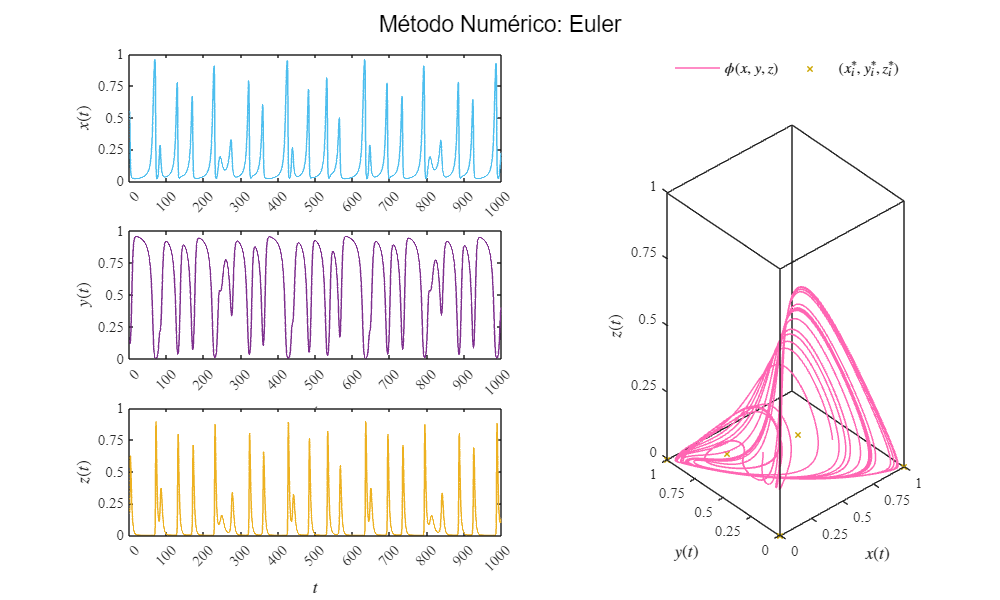

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xe,ye,ze,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Chaos.pdf'],'ContentType','vector')

## Heun

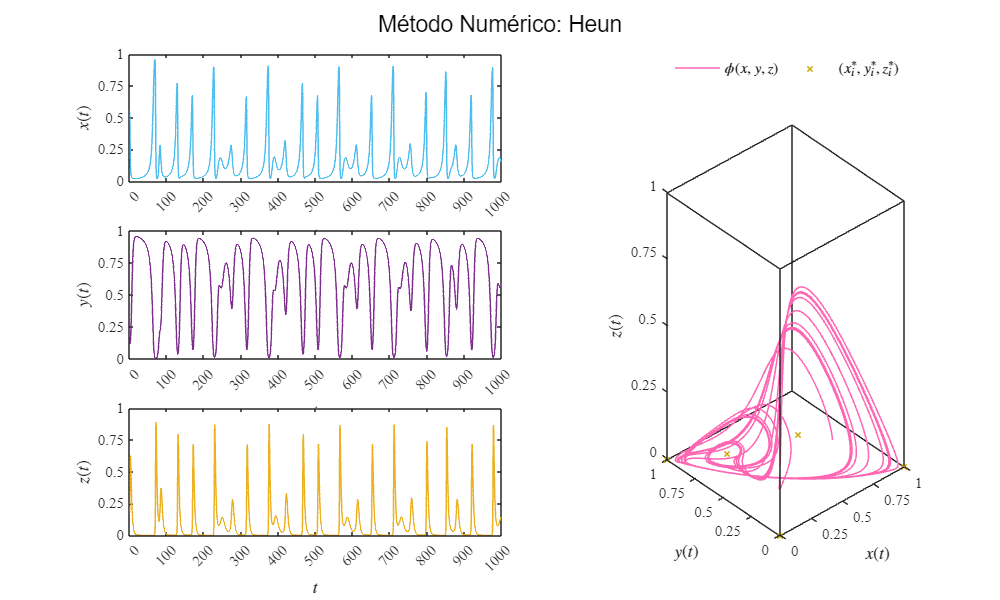

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xh,yh,zh,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Chaos.pdf'],'ContentType','vector')

## Runge-Kutta

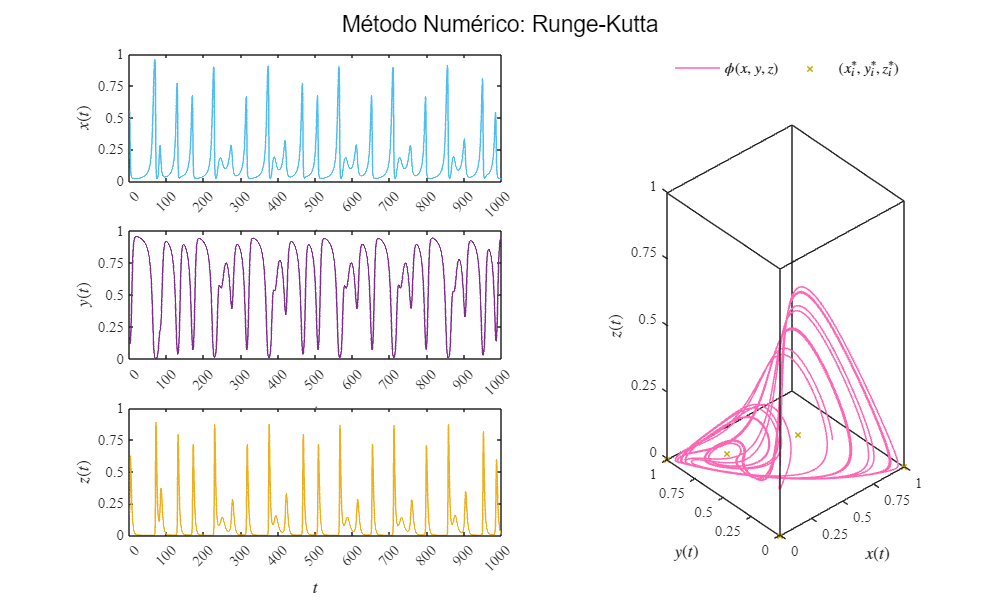

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Chaos.pdf'],'ContentType','vector')

## Comparación entre soluciones

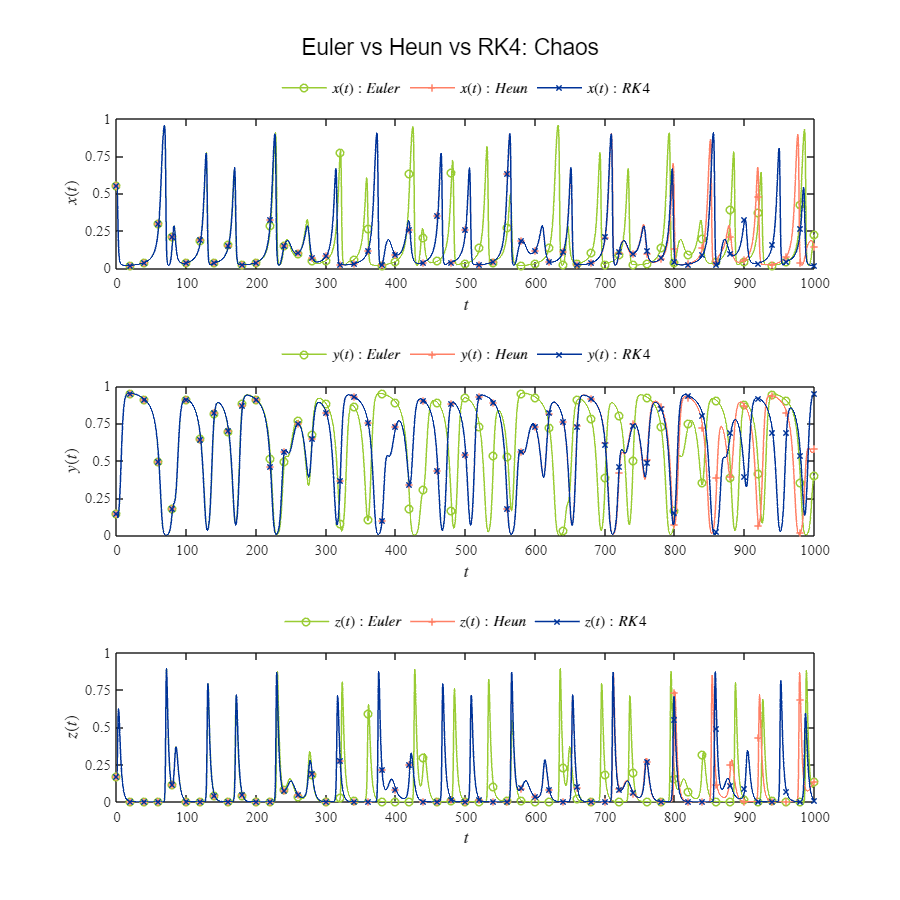

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Solution_Chaos.pdf','ContentType','vector');

### Error

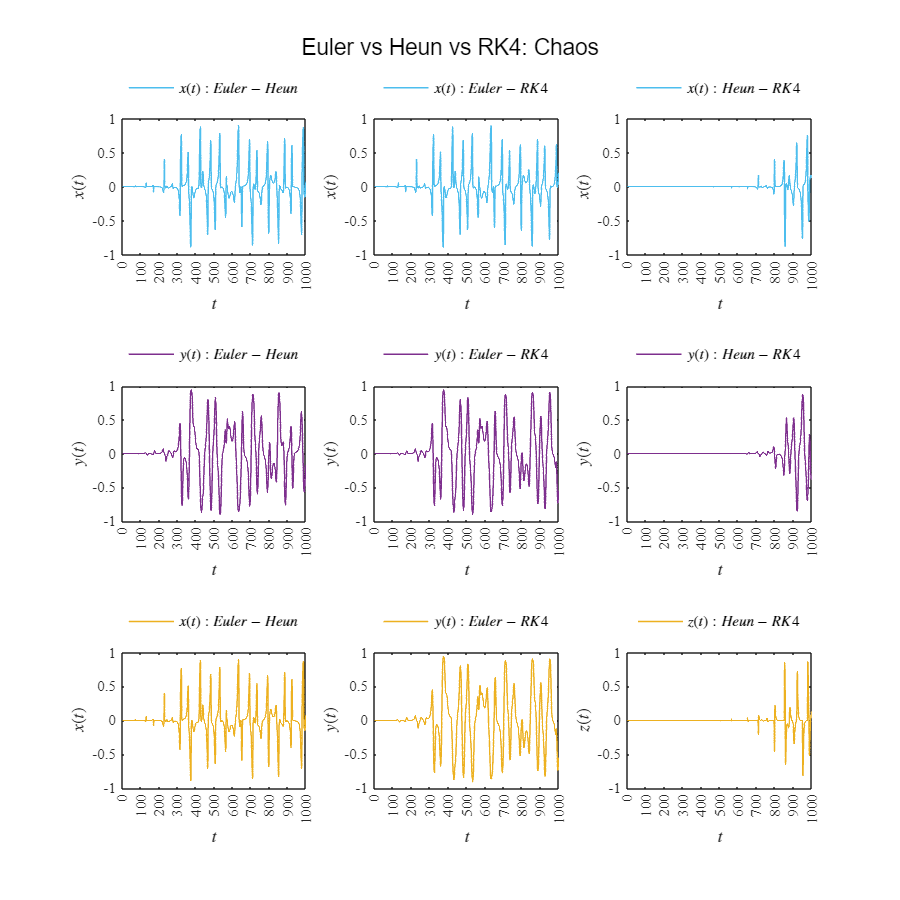

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Error_Chaos.pdf','ContentType','vector');

## Comparación de métodos numéricos: órbita periódica

D = getdata('orbit'); f0 = D.f0; par = D.par;
dt = 1E-3; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 1.141e-01)
eq3        (-8.000e-02 , 1.200e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -7.4e-02+5.8e-01i -7.4e-02-5.8e-01i +3.8e-01+0.0e+00i unstable  
eq2        -5.8e-01+0.0e+00i +2.6e-02+2.7e-01i +2.6e-02-2.7e-01i unstable  
eq3        -1.5e-01+0.0e+00i -4.9e-01+0.0e+00i -6.2e-01+0.0e+00i stable    
eq4        -6.0e-01+0.0e+00i +1.0e-01+0.0e+00i -4.0e-01+0.0e+00i unstable  
eq5        -1.0e+00+0.0e+00i -9.0e-01+0.0e+00i +2.3e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i +6.0e-01+0.0e+00i +1.0e+00+0.0e+00i uns

### Euler

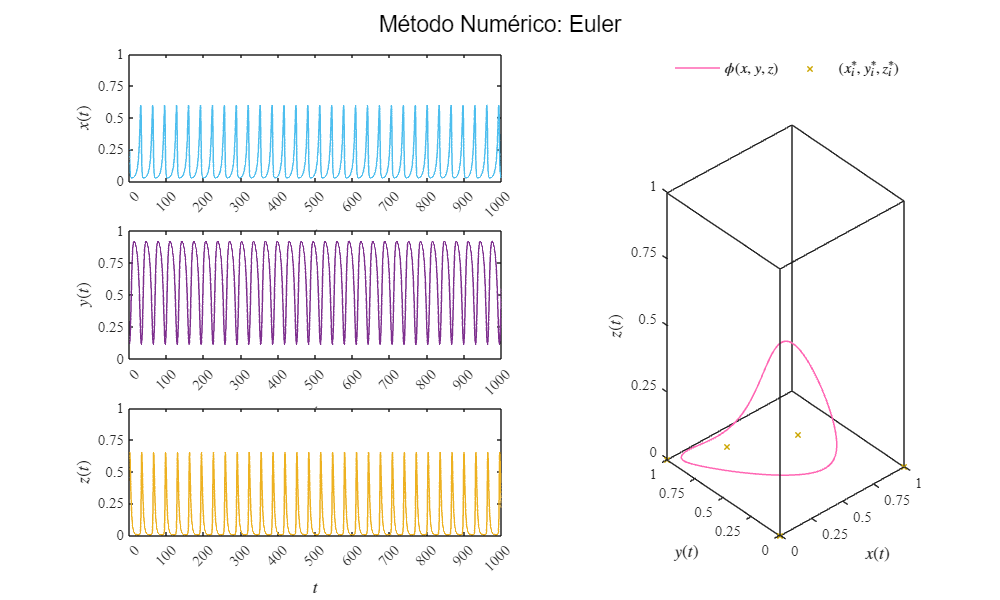

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xe,ye,ze,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Orbit.pdf'],'ContentType','vector')

## Heun

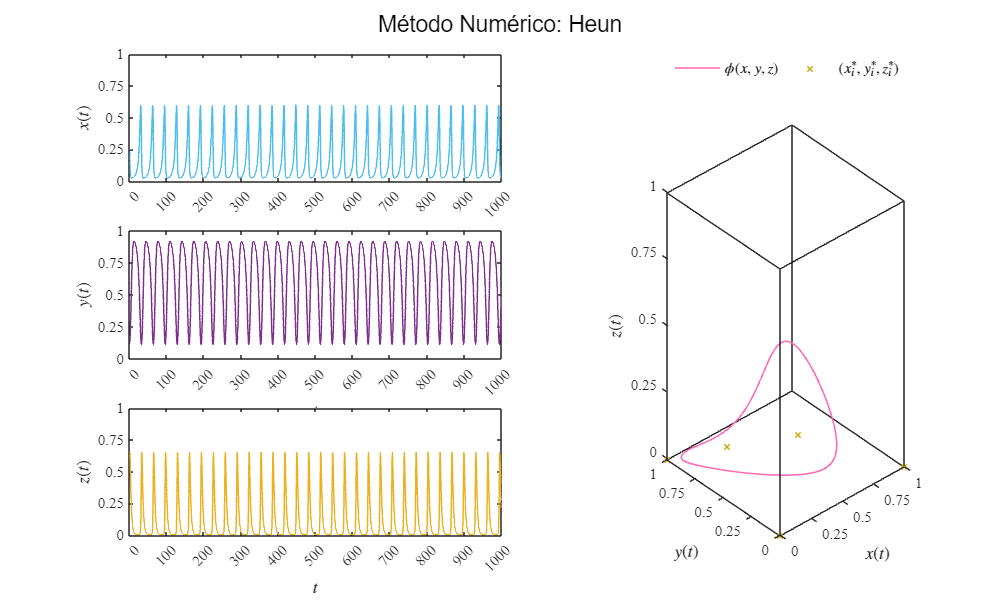

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xh,yh,zh,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Orbit.pdf'],'ContentType','vector')

## Runge-Kutta

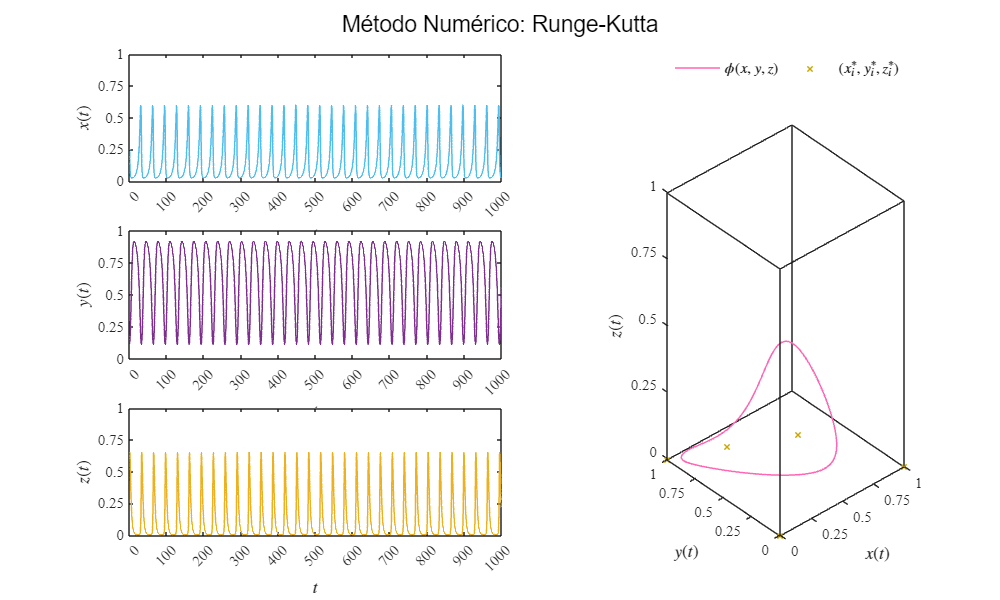

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Orbit.pdf'],'ContentType','vector')

## Comparación entre soluciones

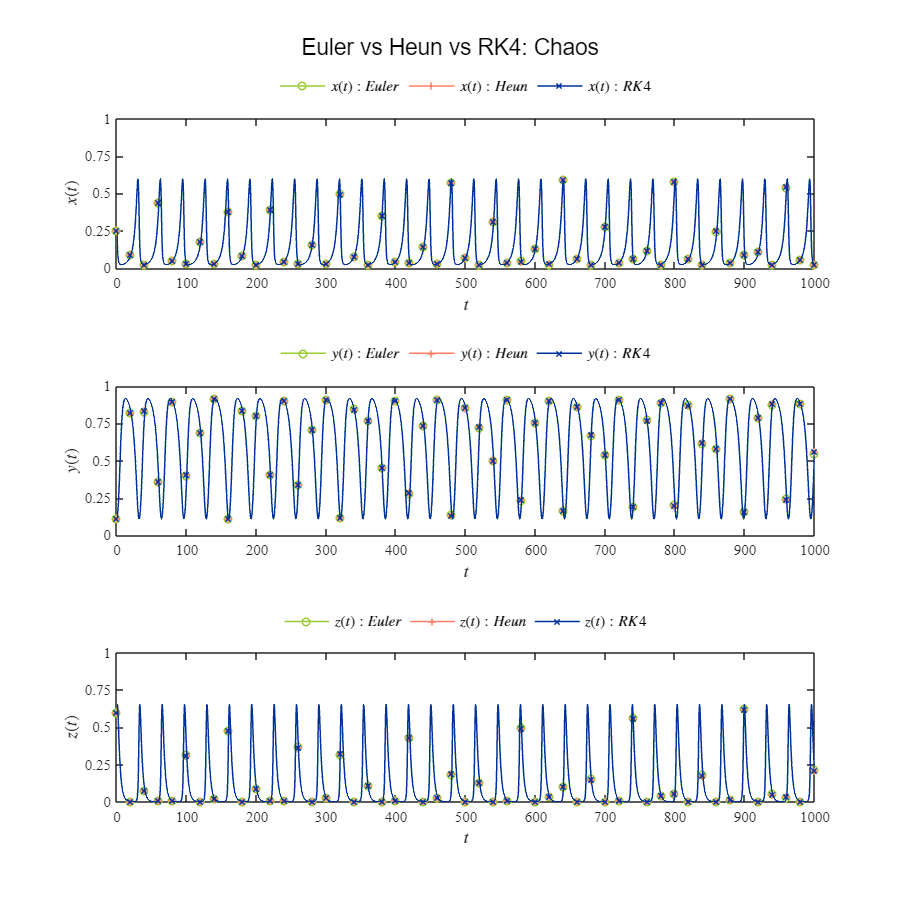

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Solution_Orbit.pdf','ContentType','vector');

### Error

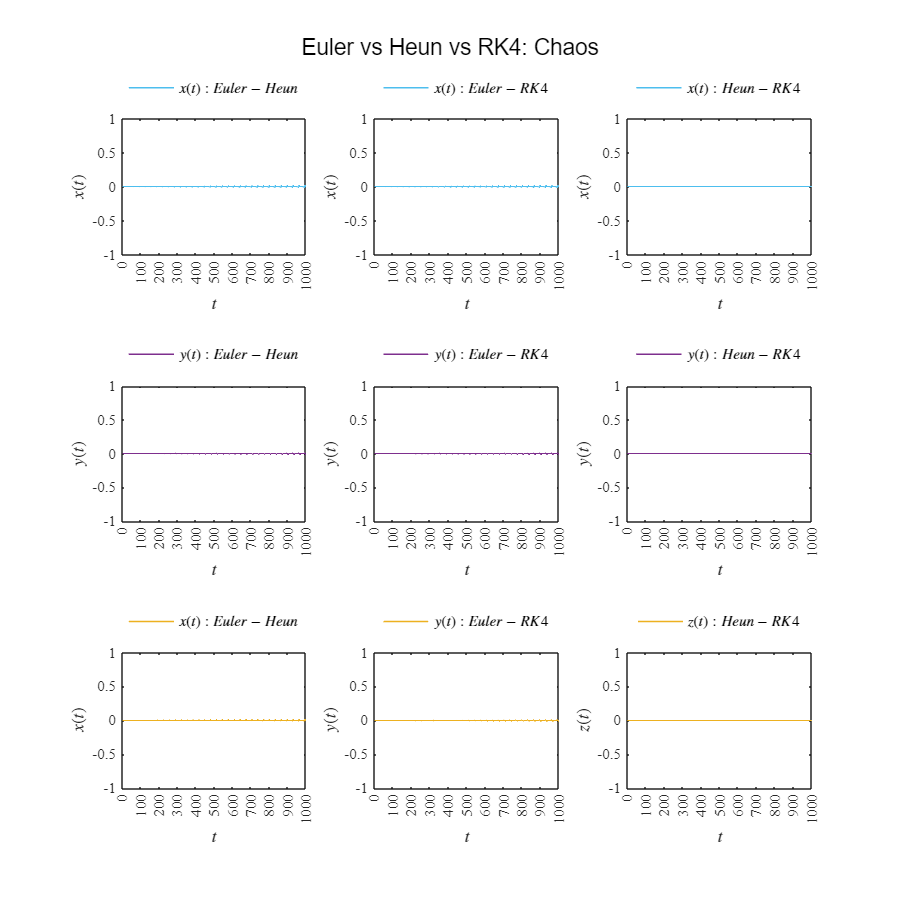

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Error_Orbit.pdf','ContentType','vector');

## Comparación de métodos numéricos: Ciclo límite 1 

D = getdata('cycle1'); f0 = D.f0; par = D.par;
dt = 1E-3; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 1.393e-01)
eq3        (-2.000e-01 , 1.500e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -7.4e-02+5.8e-01i -7.4e-02-5.8e-01i +3.8e-01+0.0e+00i unstable  
eq2        -5.5e-01+0.0e+00i +1.1e-02+3.1e-01i +1.1e-02-3.1e-01i unstable  
eq3        -3.5e-01+2.4e-01i -3.5e-01-2.4e-01i -9.4e-01+0.0e+00i stable    
eq4        -6.0e-01+0.0e+00i +2.0e-01+0.0e+00i -4.0e-01+0.0e+00i unstable  
eq5        -1.0e+00+0.0e+00i -9.0e-01+0.0e+00i +2.3e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i +6.0e-01+0.0e+00i +1.0e+00+0.0e+00i uns

### Euler

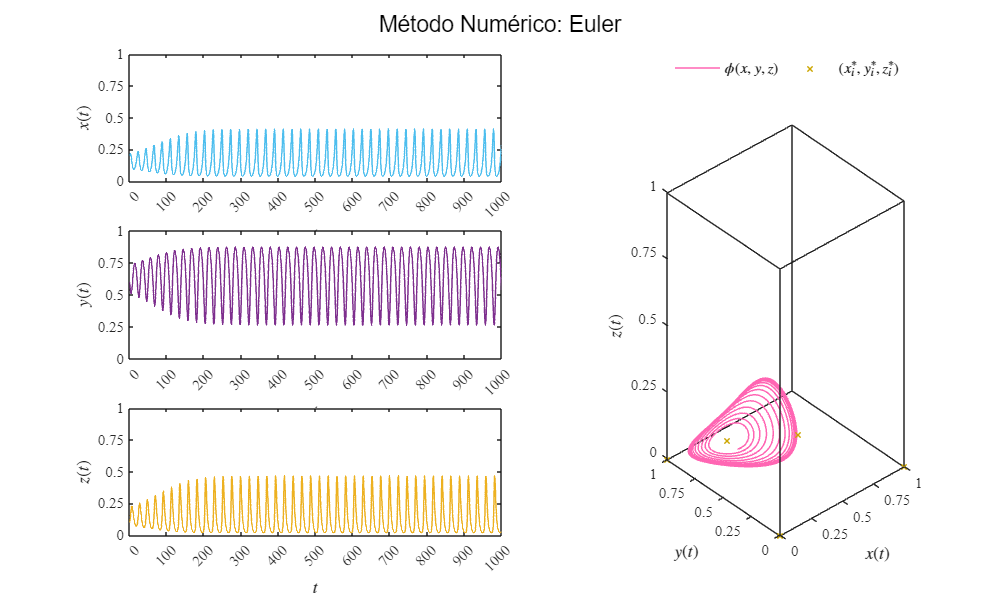

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xe,ye,ze,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Cycle1.pdf'],'ContentType','vector')

## Heun

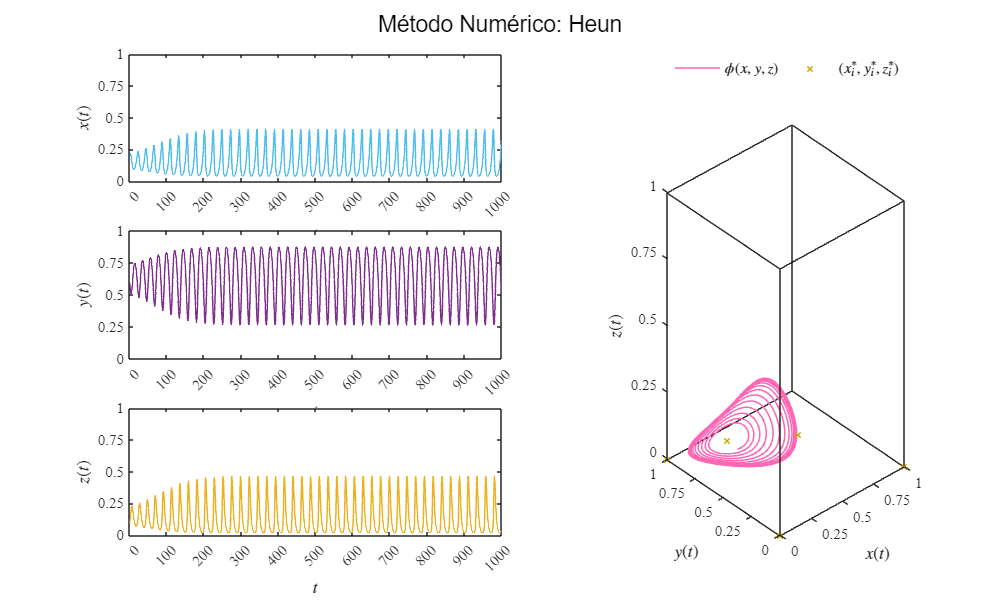

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xh,yh,zh,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Cycle1.pdf'],'ContentType','vector')

## Runge-Kutta

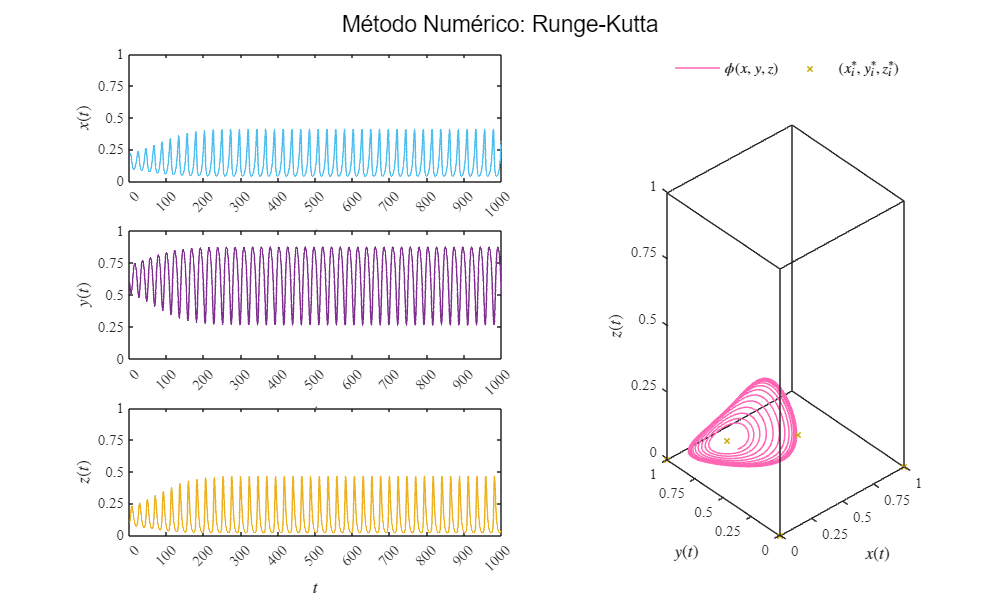

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Cycle1.pdf'],'ContentType','vector')

## Comparación entre soluciones

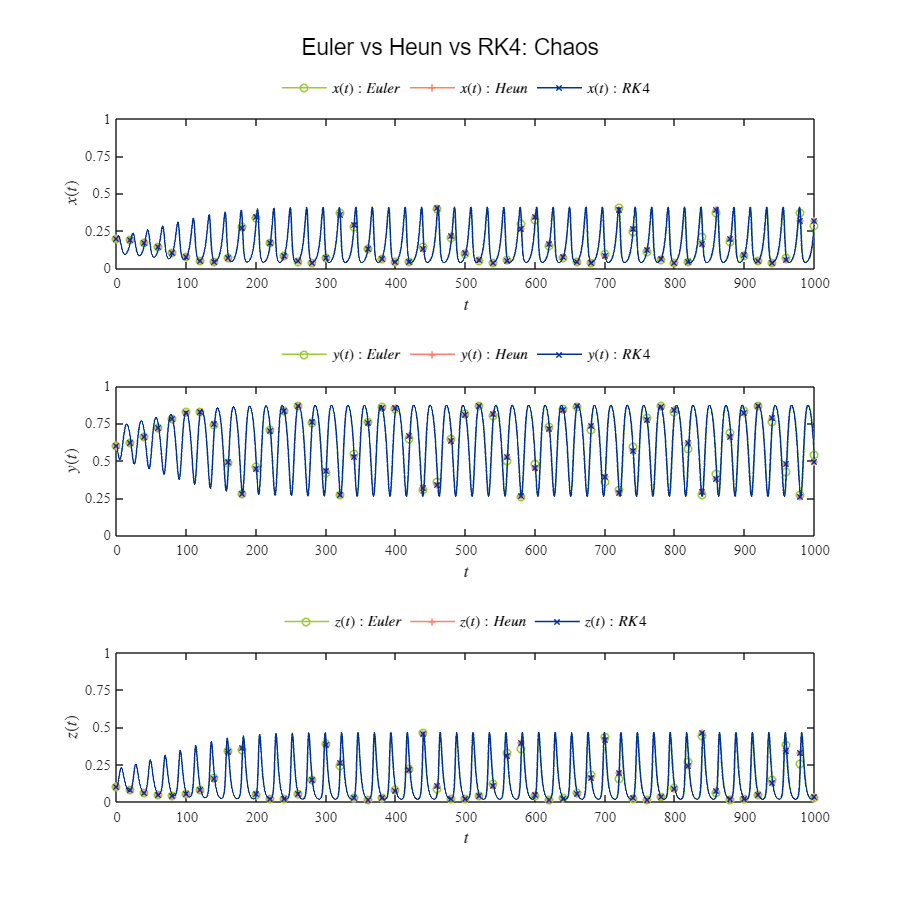

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Solution_Cycle1.pdf','ContentType','vector');

### Error

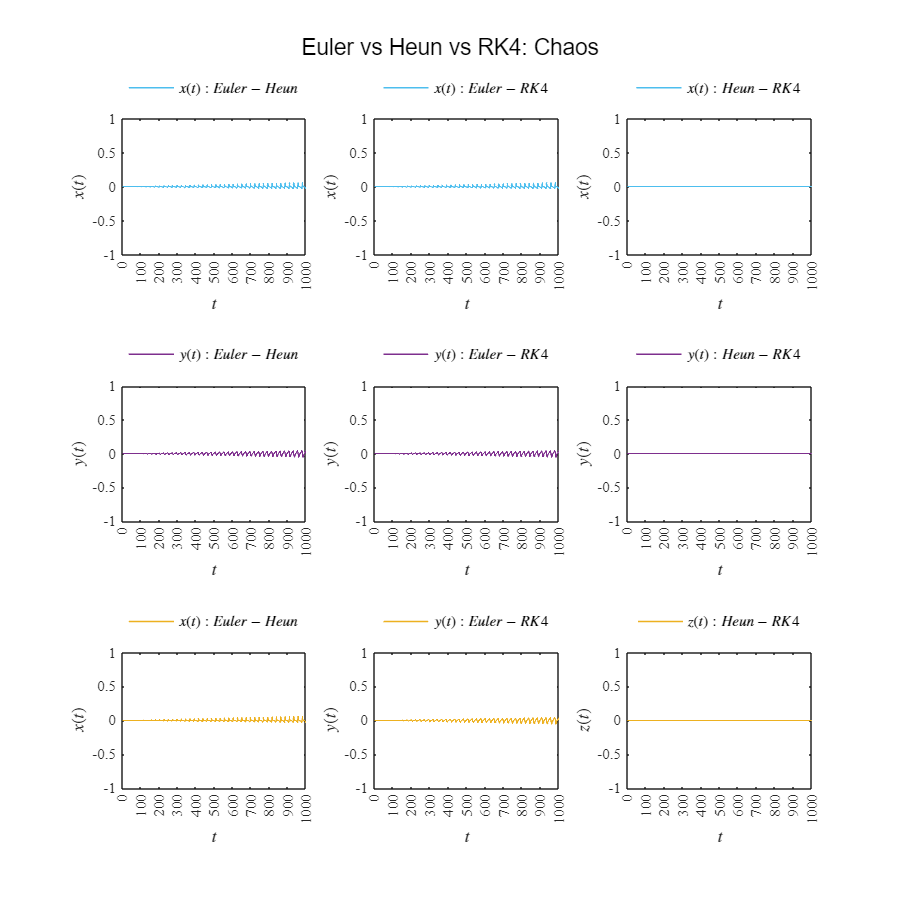

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Error_Cycle1.pdf','ContentType','vector');

## Comparación de métodos numéricos: Ciclo límite 2

D = getdata('cycle2'); f0 = D.f0; par = D.par;
dt = 1E-3; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 1.519e-01)
eq3        (-2.857e-01 , 1.714e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -7.4e-02+5.8e-01i -7.4e-02-5.8e-01i +3.8e-01+0.0e+00i unstable  
eq2        -5.3e-01+0.0e+00i +4.2e-03+3.3e-01i +4.2e-03-3.3e-01i unstable  
eq3        -3.7e-01+3.5e-01i -3.7e-01-3.5e-01i -1.2e+00+0.0e+00i stable    
eq4        -6.0e-01+0.0e+00i +2.5e-01+0.0e+00i -4.0e-01+0.0e+00i unstable  
eq5        -1.0e+00+0.0e+00i -9.0e-01+0.0e+00i +2.3e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i +6.0e-01+0.0e+00i +1.0e+00+0.0e+00i uns

### Euler

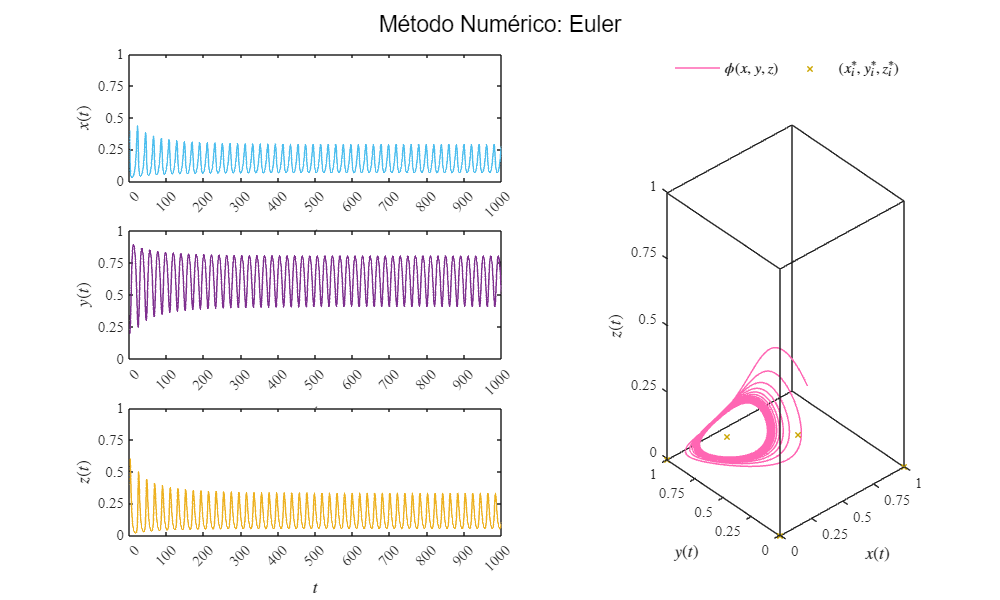

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xe,ye,ze,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Cycle2.pdf'],'ContentType','vector')

## Heun

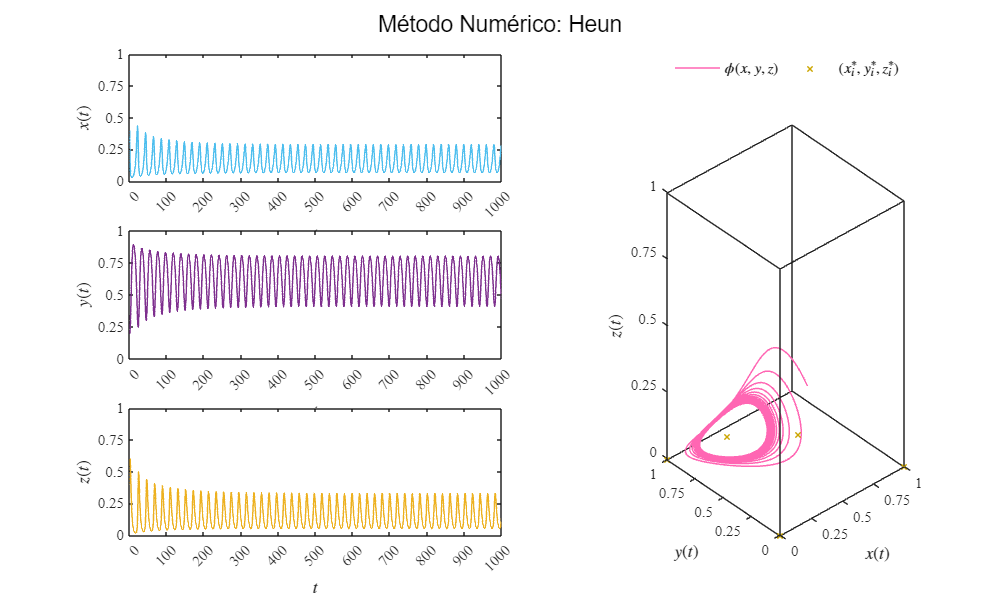

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xh,yh,zh,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Cycle2.pdf'],'ContentType','vector')

## Runge-Kutta

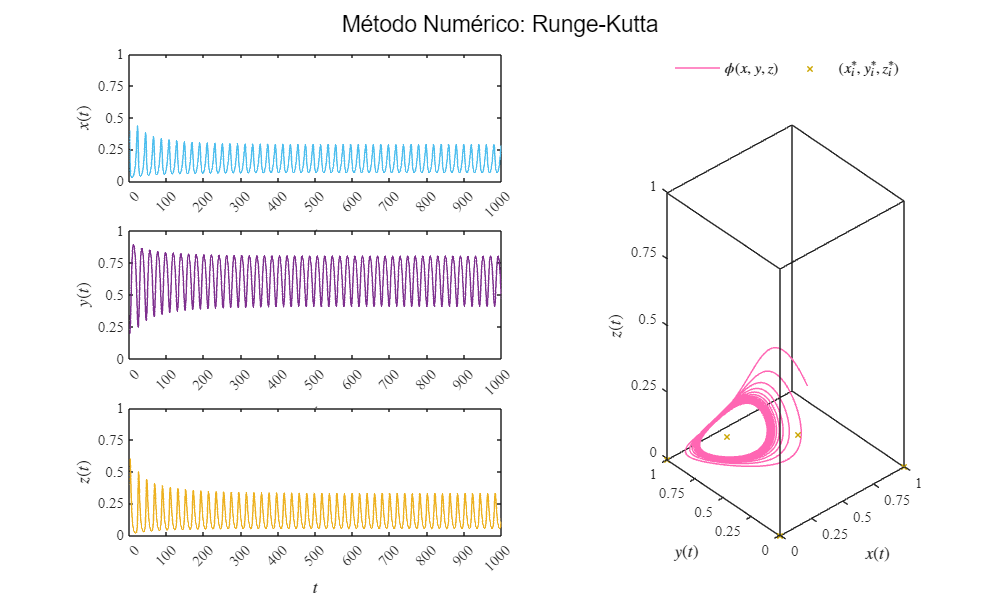

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'Cycle2.pdf'],'ContentType','vector')

## Comparación entre soluciones

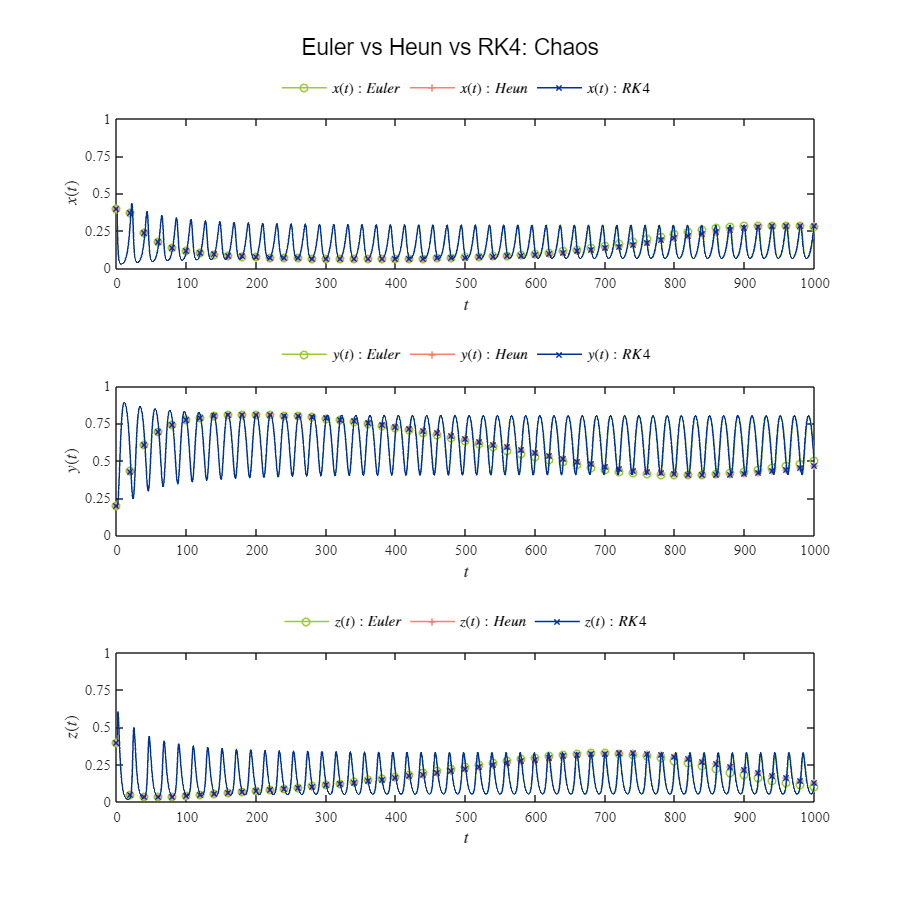

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Solution_Cycle2.pdf','ContentType','vector');

### Error

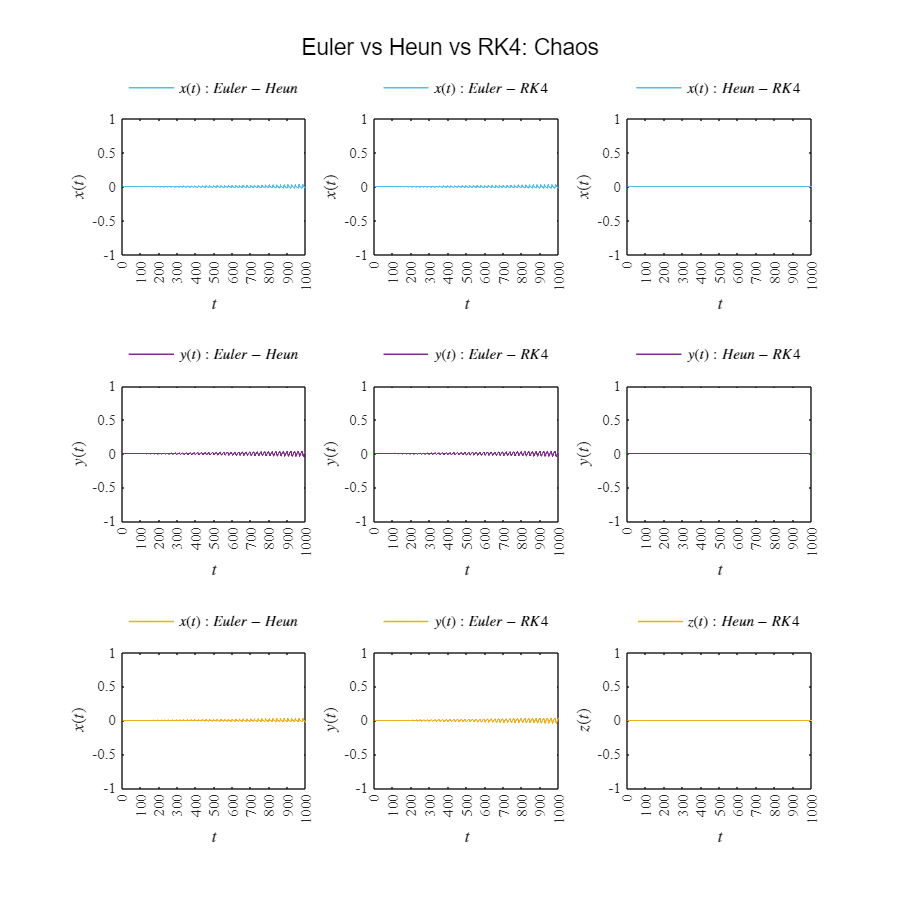

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Error_Cycle2.pdf','ContentType','vector');

## Comparación de métodos numéricos: Punto de equilibrio

D = getdata('equilibrium'); f0 = D.f0; par = D.par;
dt = 1E-3; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 2.148e-01)
eq3        (-2.000e+00 , 6.000e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -7.4e-02+5.8e-01i -7.4e-02-5.8e-01i +3.8e-01+0.0e+00i unstable  
eq2        -2.9e-02+4.2e-01i -2.9e-02-4.2e-01i -4.7e-01+0.0e+00i stable    
eq3        -8.0e-01+1.1e+00i -8.0e-01-1.1e+00i -5.8e+00+0.0e+00i stable    
eq4        -6.0e-01+0.0e+00i +5.0e-01+0.0e+00i -4.0e-01+0.0e+00i unstable  
eq5        -1.0e+00+0.0e+00i -9.0e-01+0.0e+00i +2.3e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i +6.0e-01+0.0e+00i +1.0e+00+0.0e+00i uns

### Euler

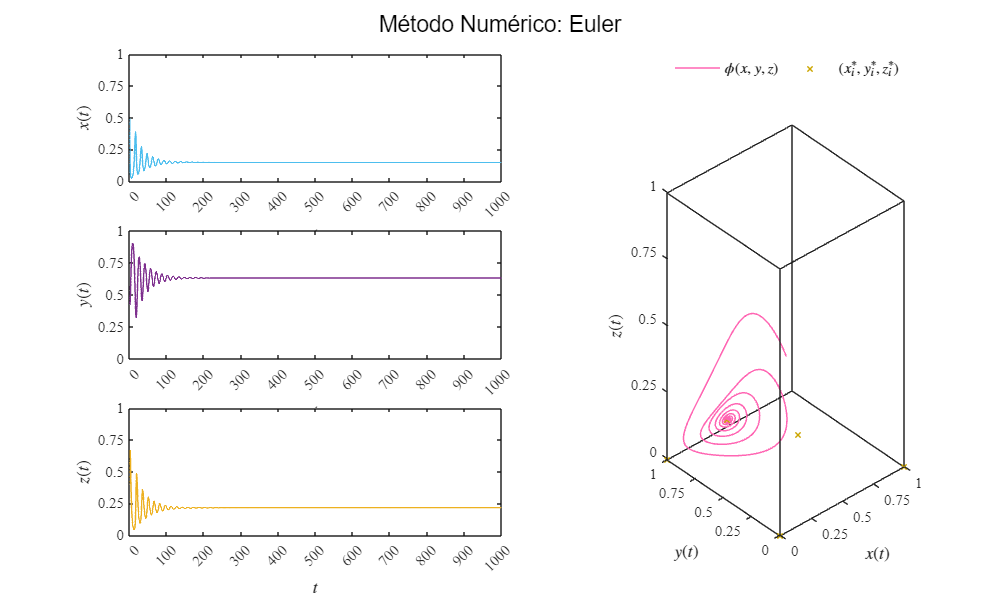

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xe,ye,ze,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'equilibrium.pdf'],'ContentType','vector')

## Heun

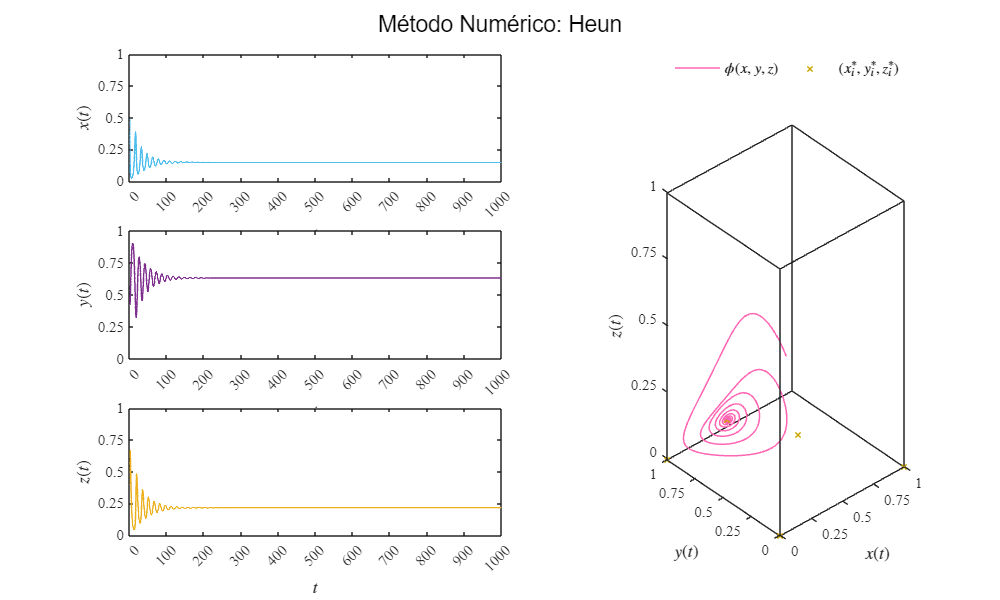

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xh,yh,zh,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'equilibrium.pdf'],'ContentType','vector')

## Runge-Kutta

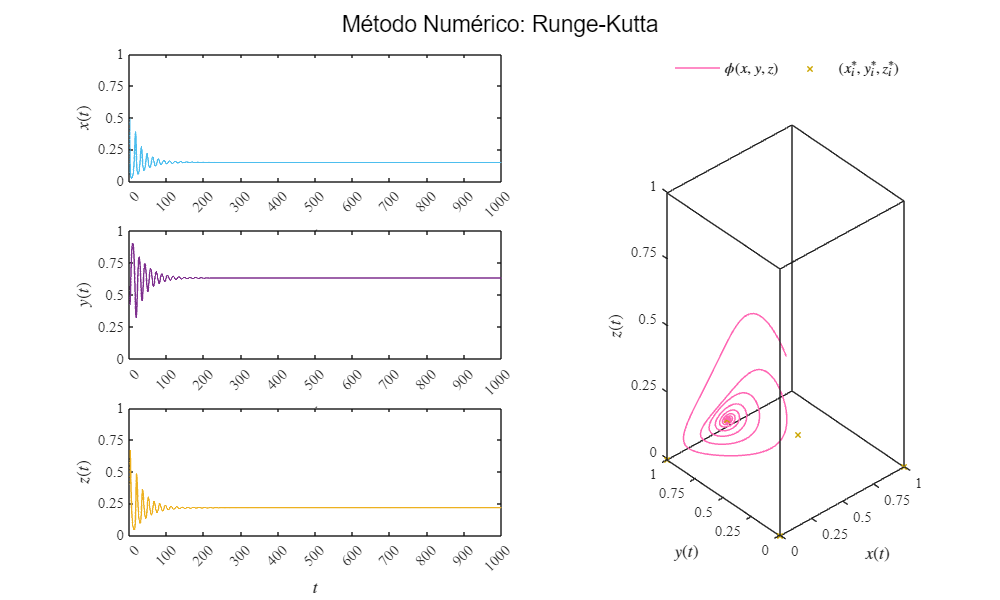

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'equilibrium.pdf'],'ContentType','vector')

## Comparación entre soluciones

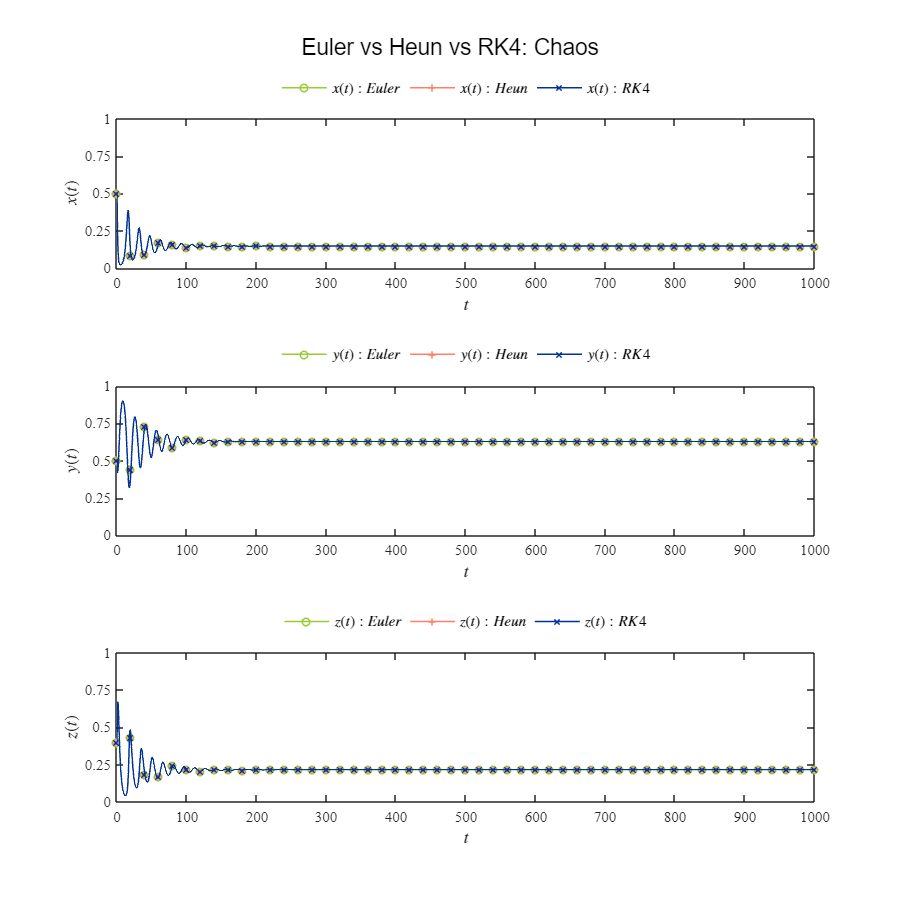

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Solution_equilibrium.pdf','ContentType','vector');

### Error

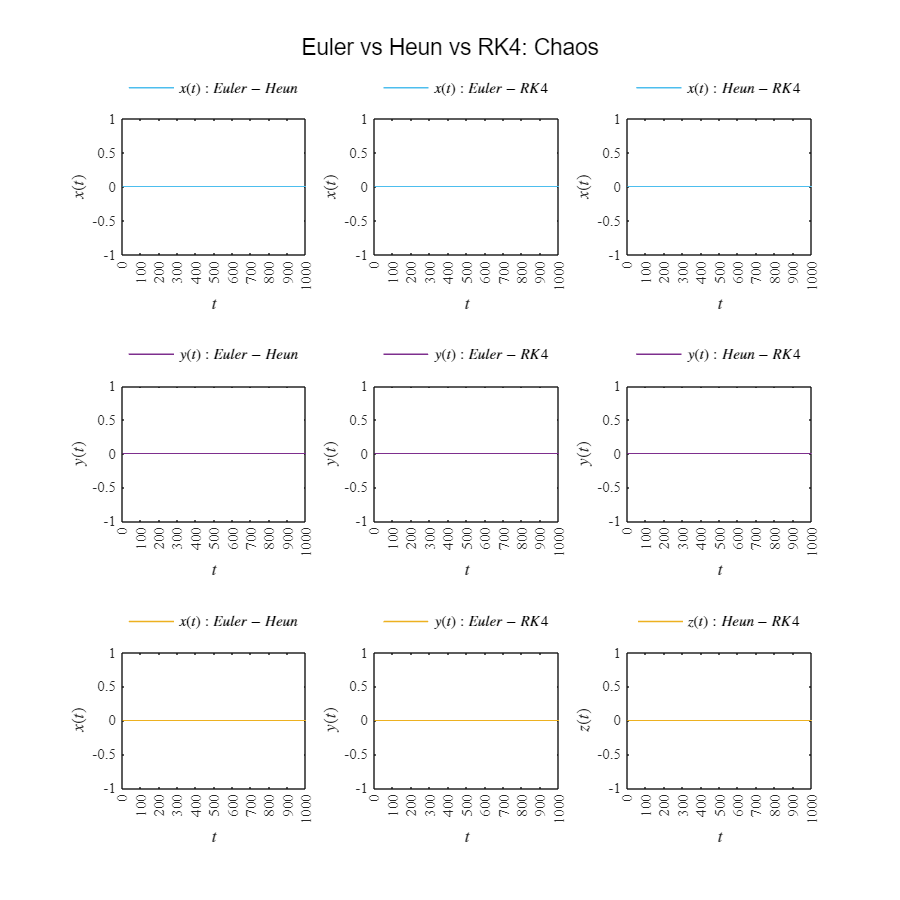

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Chaos');...
    exportgraphics(gcf,'Error_equilibrium.pdf','ContentType','vector');

## Condiciones de estabilidad asintótica

### Aplicación del tratamiento: Atractor Caótico

D = getdata('chaos'); f0 = D.f0; par = D.par;
r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); a21 = par(7); d3 = par(10);
CE = (r1 - a12/b2)*d3/a13*1.1+0.1; if CE == 0; CE = 0.1; end 
dt = 1E-3; tend = 50;
rhoi = ones(round(tend/dt)+1,1)*CE;   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 5.062e-02 , 0.000e+00 , 3.798e-01)
eq2        ( 7.407e-02 , 8.148e-01 , 4.444e-02)
eq3        ( 7.407e-02 , 8.148e-01 , 4.444e-02)
eq4        ( 0.000e+00 , 1.000e+00 , 2.500e-01)
eq5        ( 1.098e+00 , 0.000e+00 ,-3.901e-02)
eq6        ( 0.000e+00 , 0.000e+00 , 2.500e-01)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -1.6e-01+3.4e-01i -1.6e-01-3.4e-01i +5.2e-01+0.0e+00i unstable  
eq2        +4.5e-01-9.3e-02i -8.9e-01-4.6e-02i -3.3e-01-6.2e-01i unstable  
eq3        +4.5e-01+9.3e-02i -8.9e-01+4.6e-02i -3.3e-01+6.2e-01i unstable  
eq4        -4.0e-01+0.0e+00i -6.0e-01+0.0e+00i -6.2e-01+0.0e+00i stable    
eq5        -1.2e+00+0.0e+00i +2.6e+00+0.0e+00i -1.0e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i +3.8e-01+0.0e+00i +6.0e-01+0.0e+00i uns

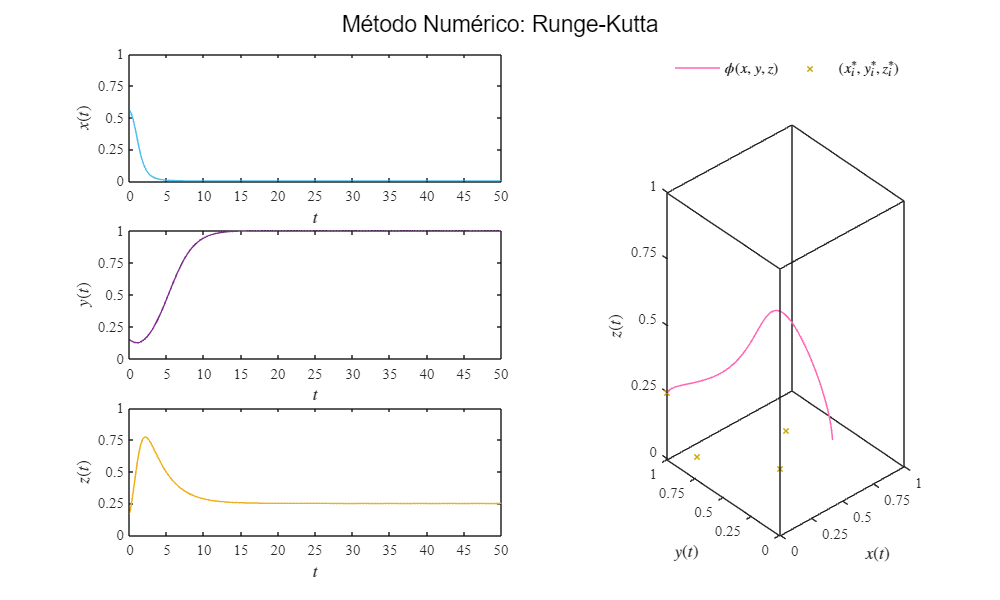

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'rhoi_chaos.pdf'],'ContentType','vector')

### Aplicación del tratamiento: órbita periódica 

D = getdata('orbit'); f0 = D.f0; par = D.par;
r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); a21 = par(7); d3 = par(10);
CE = (r1 - a12/b2)*d3/a13*1.1+0.1; if CE == 0; CE = 0.1; end 
dt = 1E-3; tend = 50;
rhoi = ones(round(tend/dt)+1,1)*CE;   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 3.528e-02 , 0.000e+00 , 3.859e-01)
eq2        ( 3.407e-02 , 9.148e-01 , 5.704e-02)
eq3        ( 3.407e-02 , 9.148e-01 , 5.704e-02)
eq4        ( 0.000e+00 , 1.000e+00 , 2.940e-01)
eq5        ( 1.113e+00 , 0.000e+00 ,-4.515e-02)
eq6        ( 0.000e+00 , 0.000e+00 , 2.940e-01)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -1.7e-01+2.7e-01i -1.7e-01-2.7e-01i +5.5e-01+0.0e+00i unstable  
eq2        +4.4e-01-1.3e-01i -9.0e-01-3.0e-02i -4.3e-01-7.1e-01i unstable  
eq3        +4.4e-01+1.3e-01i -9.0e-01+3.0e-02i -4.3e-01+7.1e-01i unstable  
eq4        -4.0e-01+0.0e+00i -6.0e-01+0.0e+00i -6.4e-01+0.0e+00i stable    
eq5        -1.2e+00+0.0e+00i +2.7e+00+0.0e+00i -1.1e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i +2.7e-01+0.0e+00i +6.0e-01+0.0e+00i uns

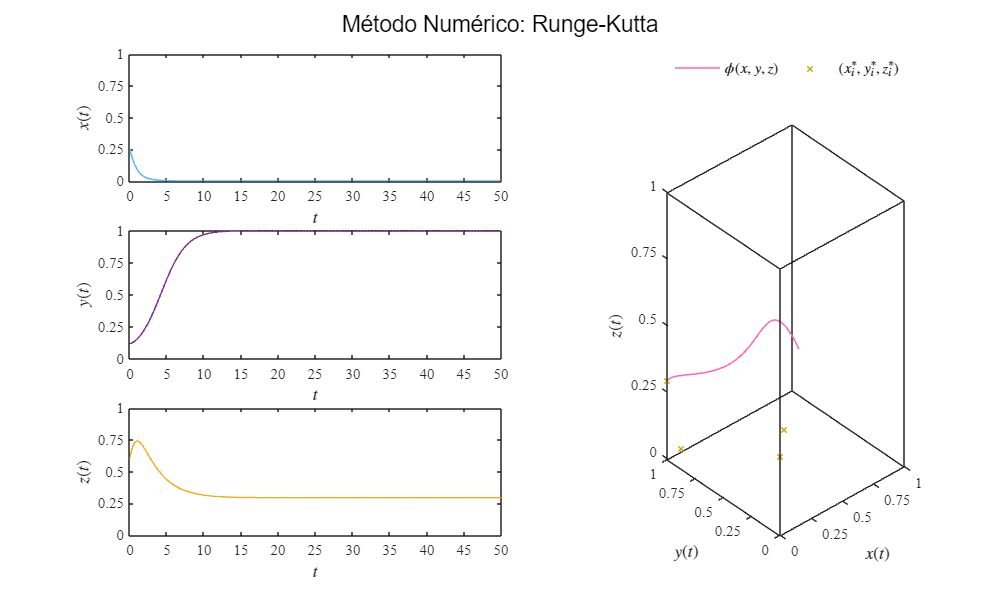

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'rhoi_orbit.pdf'],'ContentType','vector')

### Aplicación del tratamiento: ciclo límite 1

D = getdata('cycle1'); f0 = D.f0; par = D.par;
r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); a21 = par(7); d3 = par(10);
CE = (r1 - a12/b2)*d3/a13*1.1+0.1; if CE == 0; CE = 0.1; end 
dt = 1E-3; tend = 50;
rhoi = ones(round(tend/dt)+1,1)*CE;   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 2.036e-02 , 0.000e+00 , 3.919e-01)
eq2        (-2.593e-02 , 1.065e+00 , 6.963e-02)
eq3        (-2.593e-02 , 1.065e+00 , 6.963e-02)
eq4        ( 0.000e+00 , 1.000e+00 , 3.380e-01)
eq5        ( 1.128e+00 , 0.000e+00 ,-5.111e-02)
eq6        ( 0.000e+00 , 0.000e+00 , 3.380e-01)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -1.8e-01+1.7e-01i -1.8e-01-1.7e-01i +5.7e-01+0.0e+00i unstable  
eq2        +4.1e-01-1.8e-01i -9.1e-01-7.4e-03i -5.8e-01-8.0e-01i unstable  
eq3        +4.1e-01+1.8e-01i -9.1e-01+7.4e-03i -5.8e-01+8.0e-01i unstable  
eq4        -4.0e-01+0.0e+00i -6.0e-01+0.0e+00i -6.5e-01+0.0e+00i stable    
eq5        -1.2e+00+0.0e+00i +2.7e+00+0.0e+00i -1.1e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i +1.6e-01+0.0e+00i +6.0e-01+0.0e+00i uns

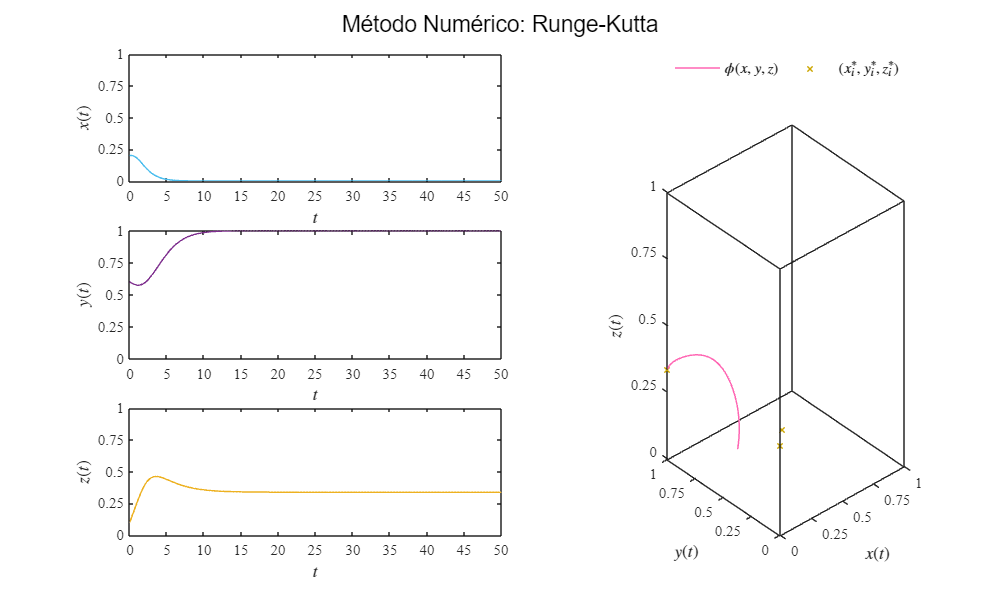

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'rhoi_cycle1.pdf'],'ContentType','vector')

### Aplicación del tratamiento: ciclo límite 2

D = getdata('cycle2'); f0 = D.f0; par = D.par;
r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); a21 = par(7); d3 = par(10);
CE = (r1 - a12/b2)*d3/a13*1.1+0.1; if CE == 0; CE = 0.1; end 
dt = 1E-3; tend = 50;
rhoi = ones(round(tend/dt)+1,1)*CE;   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.305e-02 , 0.000e+00 , 3.948e-01)
eq2        (-6.878e-02 , 1.172e+00 , 7.593e-02)
eq3        (-6.878e-02 , 1.172e+00 , 7.593e-02)
eq4        ( 0.000e+00 , 1.000e+00 , 3.600e-01)
eq5        ( 1.135e+00 , 0.000e+00 ,-5.404e-02)
eq6        ( 0.000e+00 , 0.000e+00 , 3.600e-01)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -1.9e-01+6.2e-02i -1.9e-01-6.2e-02i +5.8e-01+0.0e+00i unstable  
eq2        +3.9e-01-2.0e-01i -9.1e-01+6.9e-03i -6.9e-01-8.4e-01i unstable  
eq3        +3.9e-01+2.0e-01i -9.1e-01-6.9e-03i -6.9e-01+8.4e-01i unstable  
eq4        -4.0e-01+0.0e+00i -6.0e-01+0.0e+00i -6.5e-01+0.0e+00i stable    
eq5        -1.2e+00+0.0e+00i +2.8e+00+0.0e+00i -1.1e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i +1.0e-01+0.0e+00i +6.0e-01+0.0e+00i uns

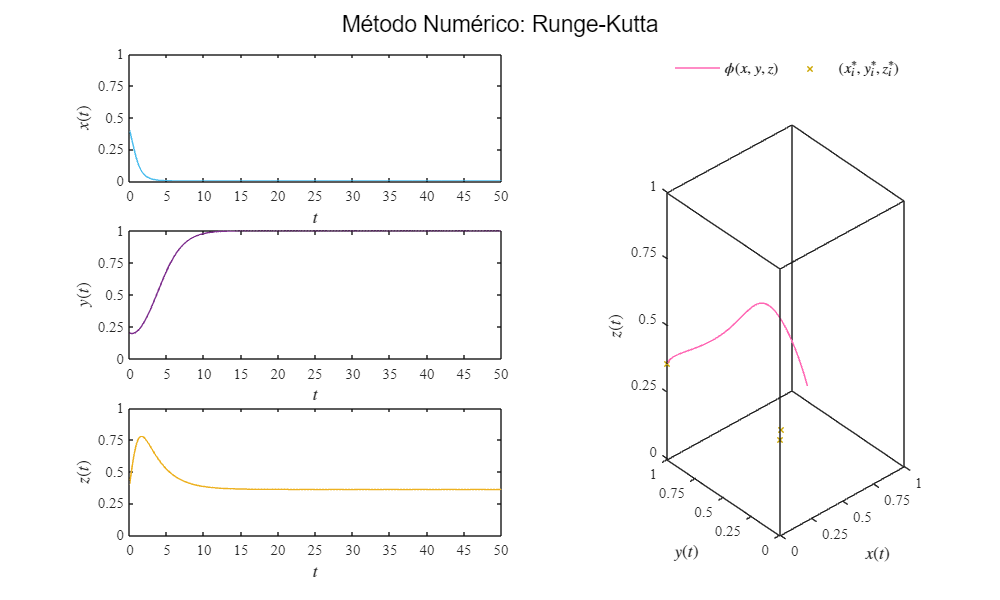

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'rhoi_cycle2.pdf'],'ContentType','vector')

### Aplicación del tratamiento: punto de equilibrio 

D = getdata('equilibrium'); f0 = D.f0; par = D.par;
r1 = par(1); a12 = par(3); a13 = par(4); b2 = par(6); a21 = par(7); d3 = par(10);
CE = (r1 - a12/b2)*d3/a13*1.1+0.1; if CE == 0; CE = 0.1; end 
dt = 1E-4; tend = 50;
rhoi = ones(round(tend/dt)+1,1)*CE;   
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        (-2.215e-02 , 0.000e+00 , 4.089e-01)
eq2        (-2.497e-01 , 1.624e+00 , 1.750e-01)
eq3        (-1.602e+00 , 5.005e+00 , 3.978e-02)
eq4        ( 0.000e+00 , 1.000e+00 , 4.700e-01)
eq5        ( 1.170e+00 , 0.000e+00 ,-6.812e-02)
eq6        ( 0.000e+00 , 0.000e+00 , 4.700e-01)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        +1.3e-01+0.0e+00i -5.6e-01+0.0e+00i +6.3e-01+0.0e+00i unstable  
eq2        +2.2e-01+0.0e+00i -8.5e-01+0.0e+00i -1.2e+00+0.0e+00i unstable  
eq3        -6.8e-01+6.8e-01i -6.8e-01-6.8e-01i -4.8e+00+0.0e+00i stable    
eq4        -4.0e-01+0.0e+00i -6.0e-01+0.0e+00i -6.7e-01+0.0e+00i stable    
eq5        -1.3e+00+0.0e+00i +2.9e+00+0.0e+00i -1.2e+00+0.0e+00i unstable  
eq6        -4.0e-01+0.0e+00i -1.7e-01+0.0e+00i +6.0e-01+0.0e+00i uns

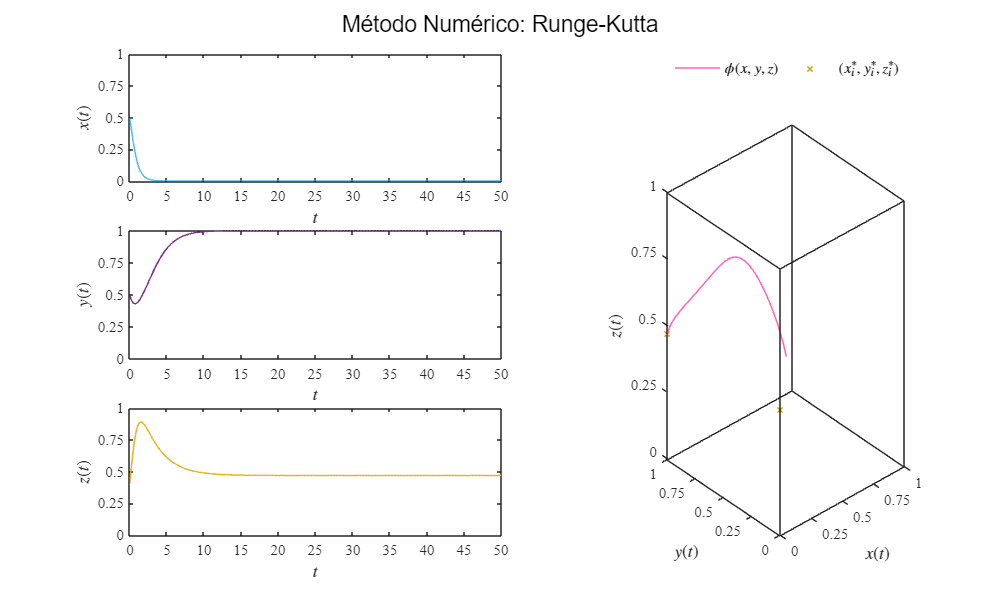

method = 'Runge-Kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOS(t,xr,yr,zr,E); sgtitle(['Método Numérico: ',method]);...
    exportgraphics(gcf,[method,'rhoi_equilibrium.pdf'],'ContentType','vector')

## Funciones

### Parámetros y condiciones iniciales

function D = getdata(dynamics)
   r1 = 1; b1 = 1; a13 = 2.5;
   r2 = 0.6; b2 = 1; a21 = 1.5; 
   r3 = 3; a31 = 0.3; d3 = 0.4;

   if dynamics == "chaos"
       a12 = 1;
       x0 = 0.555; y0 = 0.148; z0 = 0.172;
   elseif dynamics == "orbit"
       a12 = 0.9;
       x0 = 0.254781; y0 = 0.115167; z0 = 0.600527;
   elseif dynamics == "cycle1"
       a12 = 0.8;
       x0 = 0.2; y0 = 0.6; z0 = 0.1;
   elseif dynamics == "cycle2"
       a12 = 0.75;
       x0 = 0.4; y0 = 0.2; z0 = 0.4;
   elseif dynamics == "equilibrium"
       a12 = 0.5;
       x0 = 0.5; y0 = 0.5; z0 = 0.4;
   end
   D.par = [r1 b1 a12 a13 r2 b2 a21 r3 a31 d3];
   D.f0 = [x0 y0 z0];
end

      

### Métodos numéricos

function [t,x,y,z] = odesolver(method,f0,par,rhoi,tend,dt)
    method = lower(strtrim(method));
    r1 = par(1); b1 = par(2); a12 = par(3); a13 = par(4);
    r2 = par(5); b2 = par(6); a21 = par(7); 
    r3 = par(8); a31 = par(9); d3 = par(10);
    
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = f0(1);
    y = zeros(length(t),1); y(1) = f0(2);
    z = zeros(length(t),1); z(1) = f0(3);

    for i = 1:n
        switch method 
            case "euler"
                [fx,fy,fz] = f(x(i),y(i),z(i),rhoi(i));
                x(i+1) = x(i) + dt * fx;
                y(i+1) = y(i) + dt * fy;
                z(i+1) = z(i) + dt * fz;

            case "heun"
                [fx,fy,fz] = f(x(i),y(i),z(i),rhoi(i));
                xn = x(i) + dt*fx;
                yn = y(i) + dt*fy;
                zn = z(i) + dt*fz;
                [fxn, fyn, fzn] = f(xn,yn,zn,rhoi(i));
                x(i+1) = x(i) + (dt/2) * (fx + fxn);
                y(i+1) = y(i) + (dt/2) * (fy + fyn);
                z(i+1) = z(i) + (dt/2) * (fz + fzn);

            case {"rk4","runge-kutta"}
                [k1x,k1y,k1z] = f(x(i),y(i),z(i),rhoi(i));
                [k2x,k2y,k2z] = f(x(i)+(dt/2)*k1x, y(i)+(dt/2)*k1y, z(i)+(dt/2)*k1z, rhoi(i));
                [k3x,k3y,k3z] = f(x(i)+(dt/2)*k2x, y(i)+(dt/2)*k2y, z(i)+(dt/2)*k2z, rhoi(i));
                [k4x,k4y,k4z] = f(x(i)+dt*k3x, y(i)+dt*k3y, z(i)+dt*k3z, rhoi(i));
                x(i+1) = x(i) + (dt/6)*(k1x +2*k2x + 2*k3x + k4x);
                y(i+1) = y(i) + (dt/6)*(k1y +2*k2y + 2*k3y + k4y);
                z(i+1) = z(i) + (dt/6)*(k1z +2*k2z + 2*k3z + k4z);
        end
    end 
    function [dx,dy,dz] = f(x,y,z,rho)
        dx = r1*x*(1 -b1*x) - a12*x*y -a13*x*z;
        dy = r2*y*(1 -b2*y) - a21*x*y;
        dz = (r3 - a31)*x*z - d3*z + rho;
    end
h = 10;
t = t(1:1/(dt*h):end);
x = x(1:1/(dt*h):end);
y = y(1:1/(dt*h):end);
z = z(1:1/(dt*h):end);
end

### Soluciones y espacio de fase 

function plotEDOS(t,x,y,z,E)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1 1 25 15])
    FS = 10;
    c1 = [0.3010 0.7450 0.9330];
    c2 = [0.4940 0.1840 0.5560];
    c3 = [0.9290 0.6940 0.1250];
    c4 = [1 0.4 0.7];
    c8 = [0.8, 0.65, 0];

    subplot(3,6,[1 2 3]); box on; hold on;
    plot (t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(3,6,[7 8 9]); box on; hold on;
    plot (t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,6,[13 14 15]); box on; hold on;
    plot (t,z,'-','LineWidth',1,'Color',c3)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,6,[5 6 11 12 17 18]); hold on; grid off; box on; view([-42 21])
    ax = gca; ax.BoxStyle = 'full';
    plot3(x,y,z,'-','LineWidth',1,'Color',c4)
    plot3(E(:,1),E(:,2),E(:,3),'x','MarkerSize',5,'LineWidth',1,'Color',c8)
    L = legend('$\phi(x,y,z)$','$(x^*_i,y^*_i,z^*_i)$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');
    xlim([0 1]); xticks(0:0.25:1)
    ylim([0 1]); yticks(0:0.25:1)
    zlim([0 1]); zticks(0:0.25:1)
    xlabel('$x(t)$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    zlabel('$z(t)$','Interpreter','latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

%%%PLOTDIVERGENCE
function plotdivergence(t,x,y,z)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1 1 25 25])
    FS = 10;
    c5 = [0.6, 0.8, 0.2];
    c6 = [1, 0.5, 0.4];
    c7 = [0, 0.2, 0.6];
    colororder([c5;c6;c7]);

    subplot(3,1,1); box on; hold on; grid off;
    plot(t,x(:,1),'-o',t,x(:,2),'-+',t,x(:,3),'-x',...
        'LineWidth',1,'MarkerSize',5,'MarkerIndices',1:200:length(t));
    L = legend('$x(t):Euler$','$x(t):Heun$','$x(t):RK4$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');
    xlabel('$t$','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','Latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,1,2); box on; hold on; grid off;
    plot(t,y(:,1),'-o',t,y(:,2),'-+',t,y(:,3),'-x',...
        'LineWidth',1,'MarkerSize',5,'MarkerIndices',1:200:length(t));
    L = legend('$y(t):Euler$','$y(t):Heun$','$y(t):RK4$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');
    xlabel('$t$','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','Latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,1,3); box on; hold on; grid off;
    plot(t,z(:,1),'-o',t,z(:,2),'-+',t,z(:,3),'-x',...
        'LineWidth',1,'MarkerSize',5,'MarkerIndices',1:200:length(t));
    L = legend('$z(t):Euler$','$z(t):Heun$','$z(t):RK4$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlabel('$t$','Interpreter','Latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','Latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

end

%%PLOTERRORRRRR
function ploterror(t,x,y,z)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1 1 25 25])
    FS = 10;
    c1 = [0.3010 0.7450 0.9330];
    c2 = [0.4940 0.1840 0.5560];
    c3 = [0.9290 0.6940 0.1250];
   

    subplot(3,3,1); box on; hold on;
    plot (t,x(:,1) - x(:,2),'-','LineWidth',1,'Color',c1)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
     L = legend('$x(t):Euler - Heun$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

     subplot(3,3,2); box on; hold on;
    plot (t,x(:,1) - x(:,3),'-','LineWidth',1,'Color',c1)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
     L = legend('$x(t):Euler - RK4$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
     ylim([-1 1]); yticks(-1:0.5:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

     subplot(3,3,3); box on; hold on;
    plot (t,x(:,2) - x(:,3),'-','LineWidth',1,'Color',c1)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
     L = legend('$x(t):Heun - RK4$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    %%%% YYYYYYY
       subplot(3,3,4); box on; hold on;
    plot (t,y(:,1) - y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
     L = legend('$y(t):Euler - Heun$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
     ylim([-1 1]); yticks(-1:0.5:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

     subplot(3,3,5); box on; hold on;
    plot (t,y(:,1) - y(:,3),'-','LineWidth',1,'Color',c2)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
     L = legend('$y(t):Euler - RK4$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
     ylim([-1 1]); yticks(-1:0.5:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

     subplot(3,3,6); box on; hold on;
    plot (t,y(:,2) - y(:,3),'-','LineWidth',1,'Color',c2)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
     L = legend('$y(t):Heun - RK4$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
     ylim([-1 1]); yticks(-1:0.5:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
     %%%% ZZZZZZ
       subplot(3,3,7); box on; hold on;
    plot (t,x(:,1) - x(:,2),'-','LineWidth',1,'Color',c3)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
     L = legend('$x(t):Euler - Heun$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
     ylim([-1 1]); yticks(-1:0.5:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

     subplot(3,3,8); box on; hold on;
    plot (t,y(:,1) - y(:,3),'-','LineWidth',1,'Color',c3)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
     L = legend('$y(t):Euler - RK4$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
     ylim([-1 1]); yticks(-1:0.5:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

     subplot(3,3,9); box on; hold on;
    plot (t,z(:,2) - z(:,3),'-','LineWidth',1,'Color',c3)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
     L = legend('$z(t):Heun - RK4$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation', 'Horizontal');    
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
       
   

    
end


## Equilibrios 

function [E,lambda] = equilibria(par,rhoi)
r1 = par(1); b1 = par(2); a12 = par(3); a13 = par(4);
r2 = par(5); b2 = par(6); a21 = par(7);
r3 = par(8); a31 = par(9); d3 = par(10);

e1 = [(r1 - (a13*(a31*r1 - r1*r3 - sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rhoi*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rhoi*b1*r3 + r1*r3^2)) + b1*d3*r1))/(2*(a13*a31 - a13*r3)))/(b1*r1); 0; (a31*r1 - r1*r3 - sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rhoi*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rhoi*b1*r3 + r1*r3^2)) + b1*d3*r1)/(2*(a13*a31 - a13*r3))];
e2 = [(r2*(a12 - b2*r1))/(a12*a21 - b1*b2*r1*r2) - (sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); (a21*r1 - b1*r1*r2)/(a12*a21 - b1*b2*r1*r2) + (a21*(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); -(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))];
e3 = [(r2*(a12 - b2*r1))/(a12*a21 - b1*b2*r1*r2) + (sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); (a21*r1 - b1*r1*r2)/(a12*a21 - b1*b2*r1*r2) - (a21*(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); (sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))];
e4 = [0; 1/b2; rhoi/d3];
e5 = [(r1 - (a13*(a31*r1 - r1*r3 + sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rhoi*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rhoi*b1*r3 + r1*r3^2)) + b1*d3*r1))/(2*(a13*a31 - a13*r3)))/(b1*r1); 0; (a31*r1 - r1*r3 + sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rhoi*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rhoi*b1*r3 + r1*r3^2)) + b1*d3*r1)/(2*(a13*a31 - a13*r3))];
e6 = [0; 0; rhoi/d3];
E = [e1,e2,e3,e4,e5,e6]; E = double(E)'; E(E>-1e-12 & E<1e-12) = 0;
names = {'eq1';'eq2';'eq3';'eq4';'eq5';'eq6'};
fprintf('%-11s | %-9s | %-9s | %-9s|\n','Equilibria', ' x*', ' y*', ' z*');
fprintf('-------------------------------------------------\n');
for i = 1:length(E)
fprintf('%-10s (%10.3e ,%10.3e ,%10.3e)\n', names{i}, E(i,1), E(i,2), E(i,3));
end
x = E(:,1); y = E(:,2); z = E(:,3); lr = zeros(length(E),3); li = zeros(length(E),3); stability = cell(length(E),1);
for i = 1:length(E)
J = [- a12*y(i) - a13*z(i) - r1*(b1*x(i) - 1) - b1*r1*x(i), -a12*x(i), -a13*x(i);
- a21*y(i), - a21*x(i) - r2*(b2*y(i) - 1) - b2*r2*y(i), 0;
- z(i)*(a31 - r3), 0, - d3 - x(i)*(a31 - r3)];

lr(i,:) = real(eig(J)); lr(lr>-1e-12 & lr<1e-12) = 0;
li(i,:) = imag(eig(J));
if all(lr(i,:) < 0)
stability{i,1} = 'stable';
elseif any(lr(i,:) > 0)
stability{i,1} = 'unstable';
else
stability{i,1} = 'unidentified';
end
end
lambda = lr + 1i*li;

fprintf('\n\n%-10s | %-16s | %-16s | %-16s| %-10s|\n','Equilibria', ' lambda 1', ' lambda 2', ' lambda 3', 'stability');
fprintf('---------------------------------------------------------------------------------\n');
for i = 1:length(E)
fprintf('%-10s %+.1e%+.1ei %+.1e%+.1ei %+.1e%+.1ei %-10s\n', names{i}, real(lambda(i,1)),imag(lambda(i,1)), ...
real(lambda(i,2)),imag(lambda(i,2)), real(lambda(i,3)),imag(lambda(i,3)), stability{i});
end
end